data_paths=...
    {'/Volumes/PcSSDA/1626/20220313_1626_SW_002', '/Volumes/PcSSDA/1626/20220318_1626_SW_003', '/Volumes/PcSSDA/1626/20220329_1626_SW_004',...
    '/Volumes/PcSSDA/1627/20220317_1627_SW_002', '/Volumes/PcSSDA/1627/20220322_1627_SW_003', '/Volumes/PcSSDA/1627/20220402_1627_SW_004',...
    '/Volumes/PcSSDA/1629/20220312_1629_SW_002', '/Volumes/PcSSDA/1629/20220323_1629_SW_003', '/Volumes/PcSSDA/1629/20220331_1629_SW_004',...
    '/Volumes/PcSSDA/1630/20220304_1630_SW_002', '/Volumes/PcSSDA/1630/20220319_1630_SW_003', '/Volumes/PcSSDA/1630/20220330_1630_SW_004',...
    '/Volumes/PcSSDA/1612/20220301_1612_SW_003', '/Volumes/PcSSDA/1612/20220315_1612_SW_004', '/Volumes/PcSSDA/1612/20220324_1612_SW_005',...
    '/Volumes/PcSSDA/1611/20220302_1611_SW_003', '/Volumes/PcSSDA/1611/20220316_1611_SW_004', '/Volumes/PcSSDA/1611/20220325_1611_SW_005',...
    '/Volumes/PcSSDA/1610/20220219_1610_SW_002', '/Volumes/PcSSDA/1610/20220314_1610_SW_003', '/Volumes/PcSSDA/1610/20220328_1610_SW_005',...
    '/Volumes/PcSSDA/20220422_112_AChmtut_SW_001', '/Volumes/PcSSDA/20220206_112_8_AChMut_SW_001', '/Volumes/PcSSDA/20220206_112_8_AChMut_SW_001',...
    '/Volumes/PcSSDA/20220425_109_AChmut_SW_001', '/Volumes/PcSSDA/20220207_109_AChMut_SW_001', '/Volumes/PcSSDA/20220207_109_AChMut_SW_001',...
    };

animal_IDs=...
    {'1626',...
    '1627',...
    '1629',...
    '1630',...
    '1612',...
    '1611',...
    '1610',...
    '112',...
    '109',...
    };


Loading wave object  ...
Loading wave object  ...
Loading wave object  ...


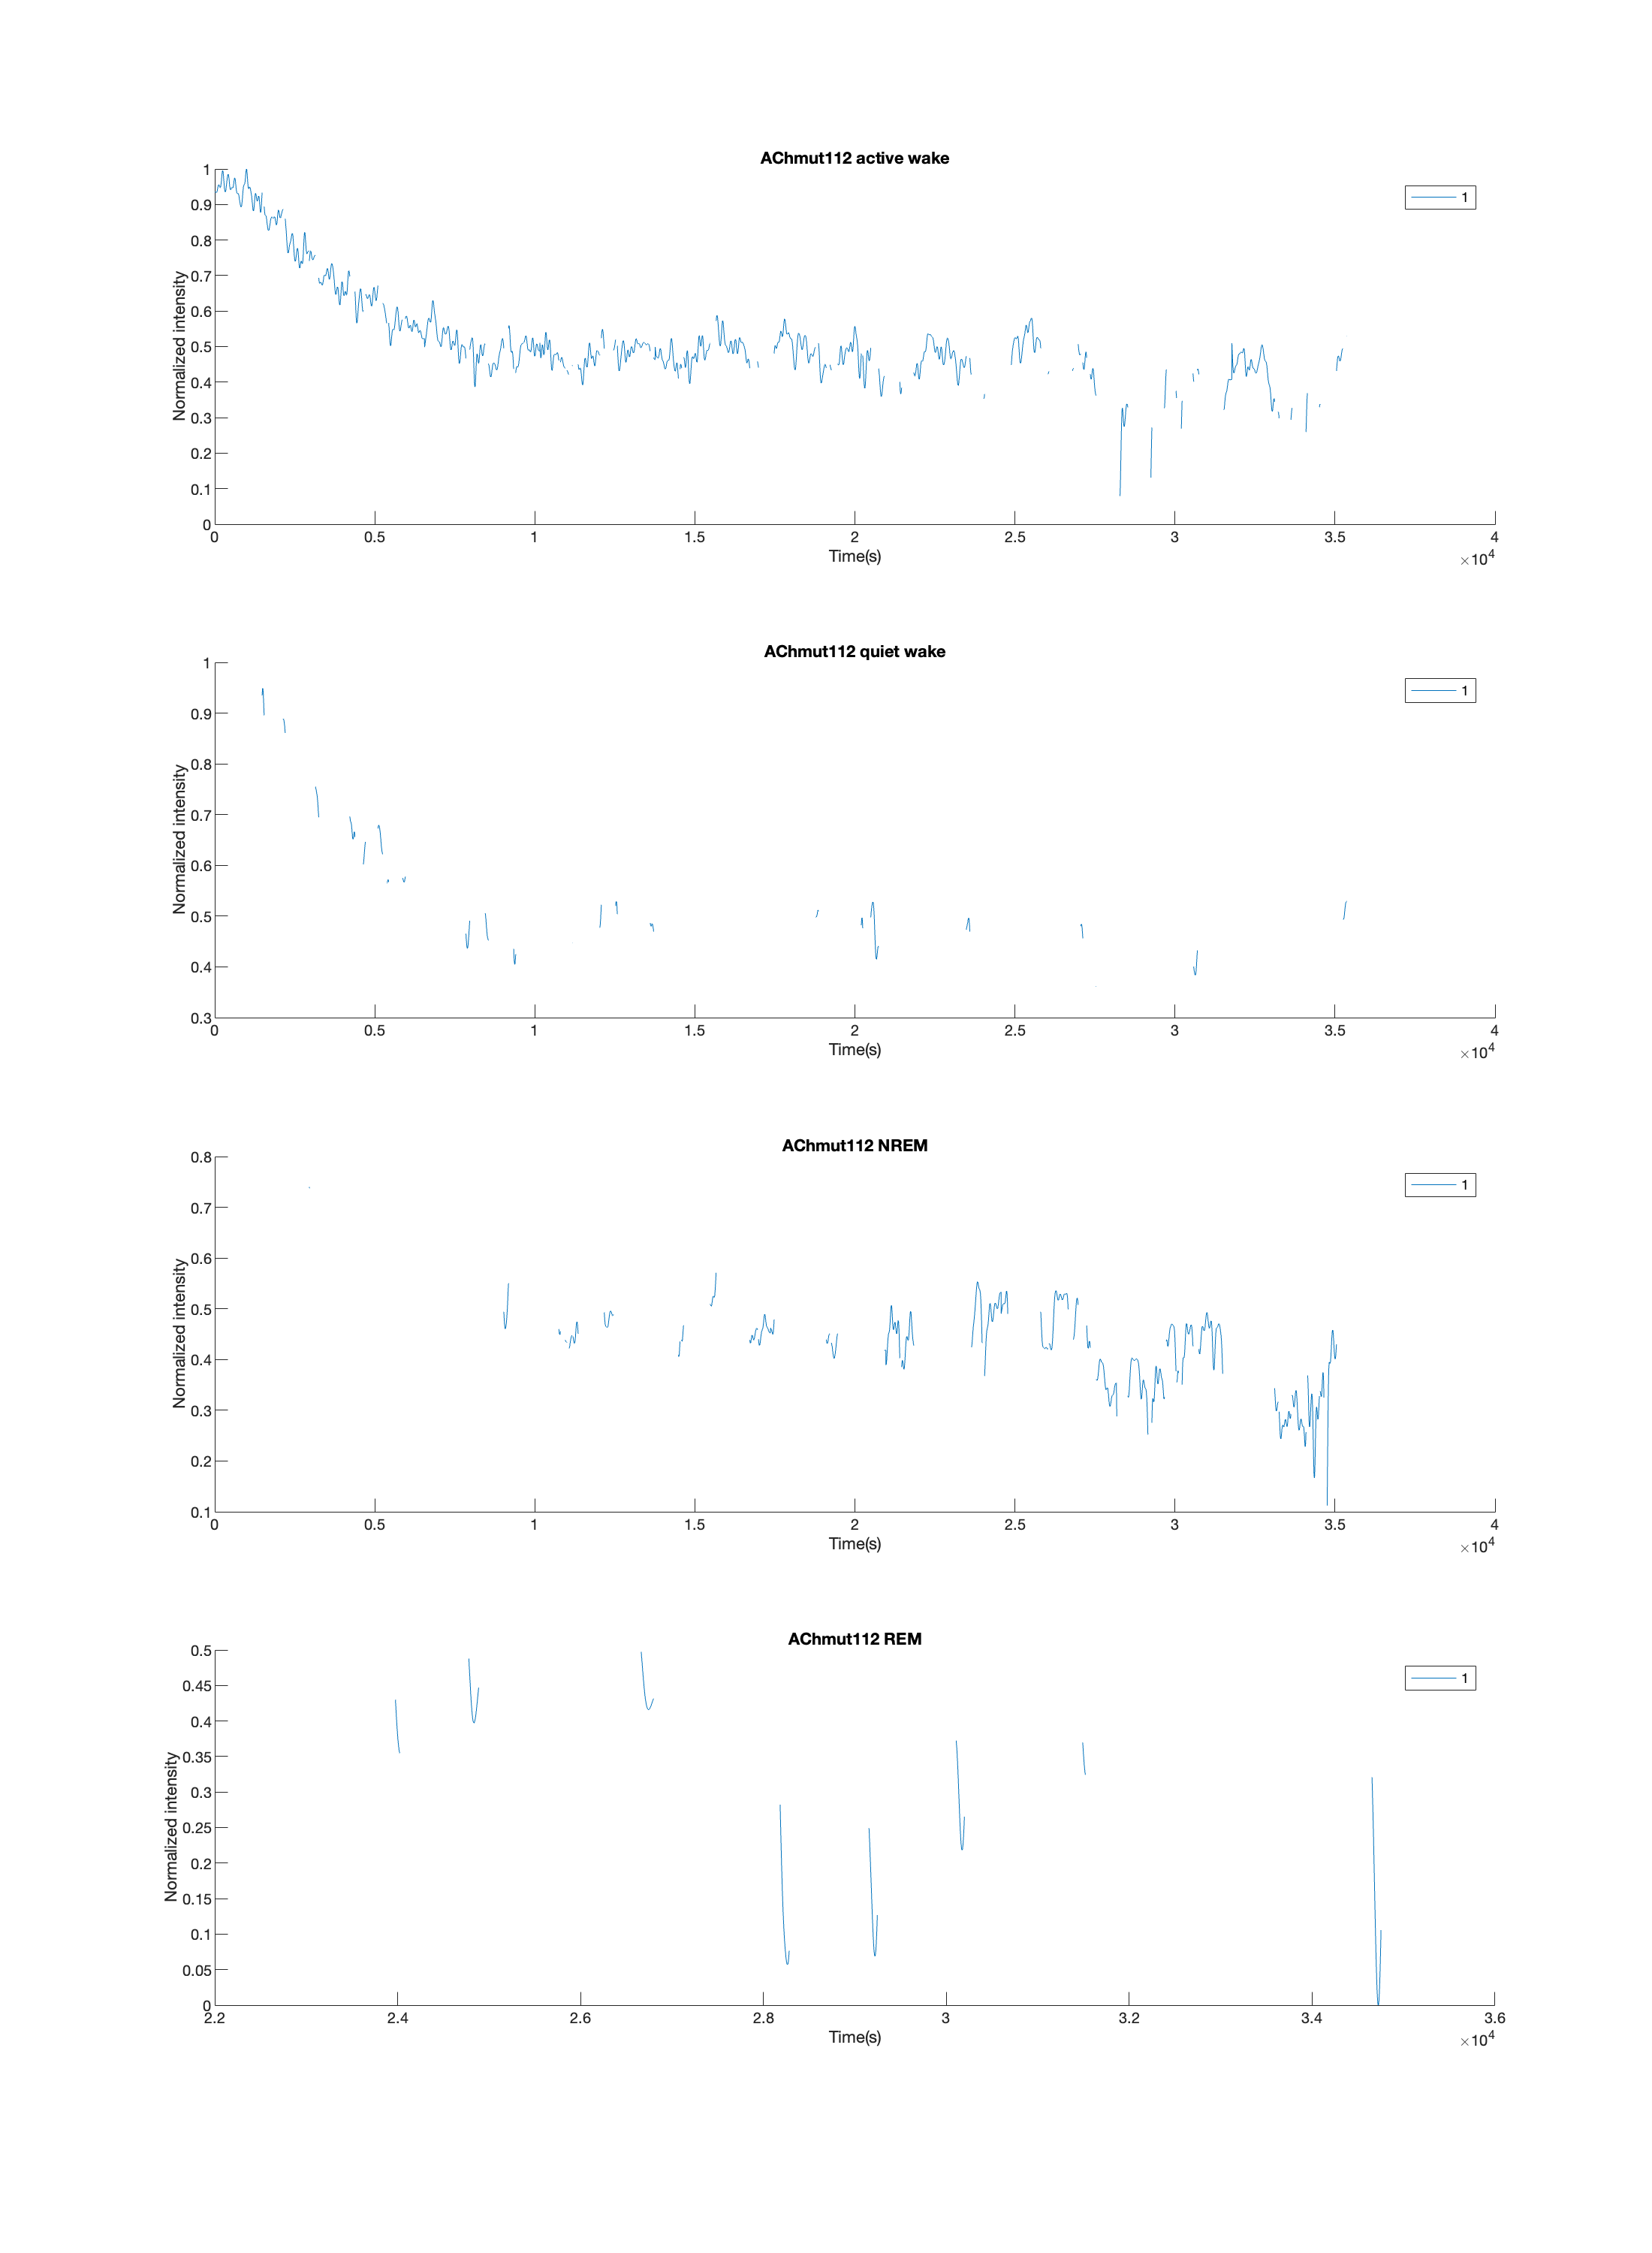

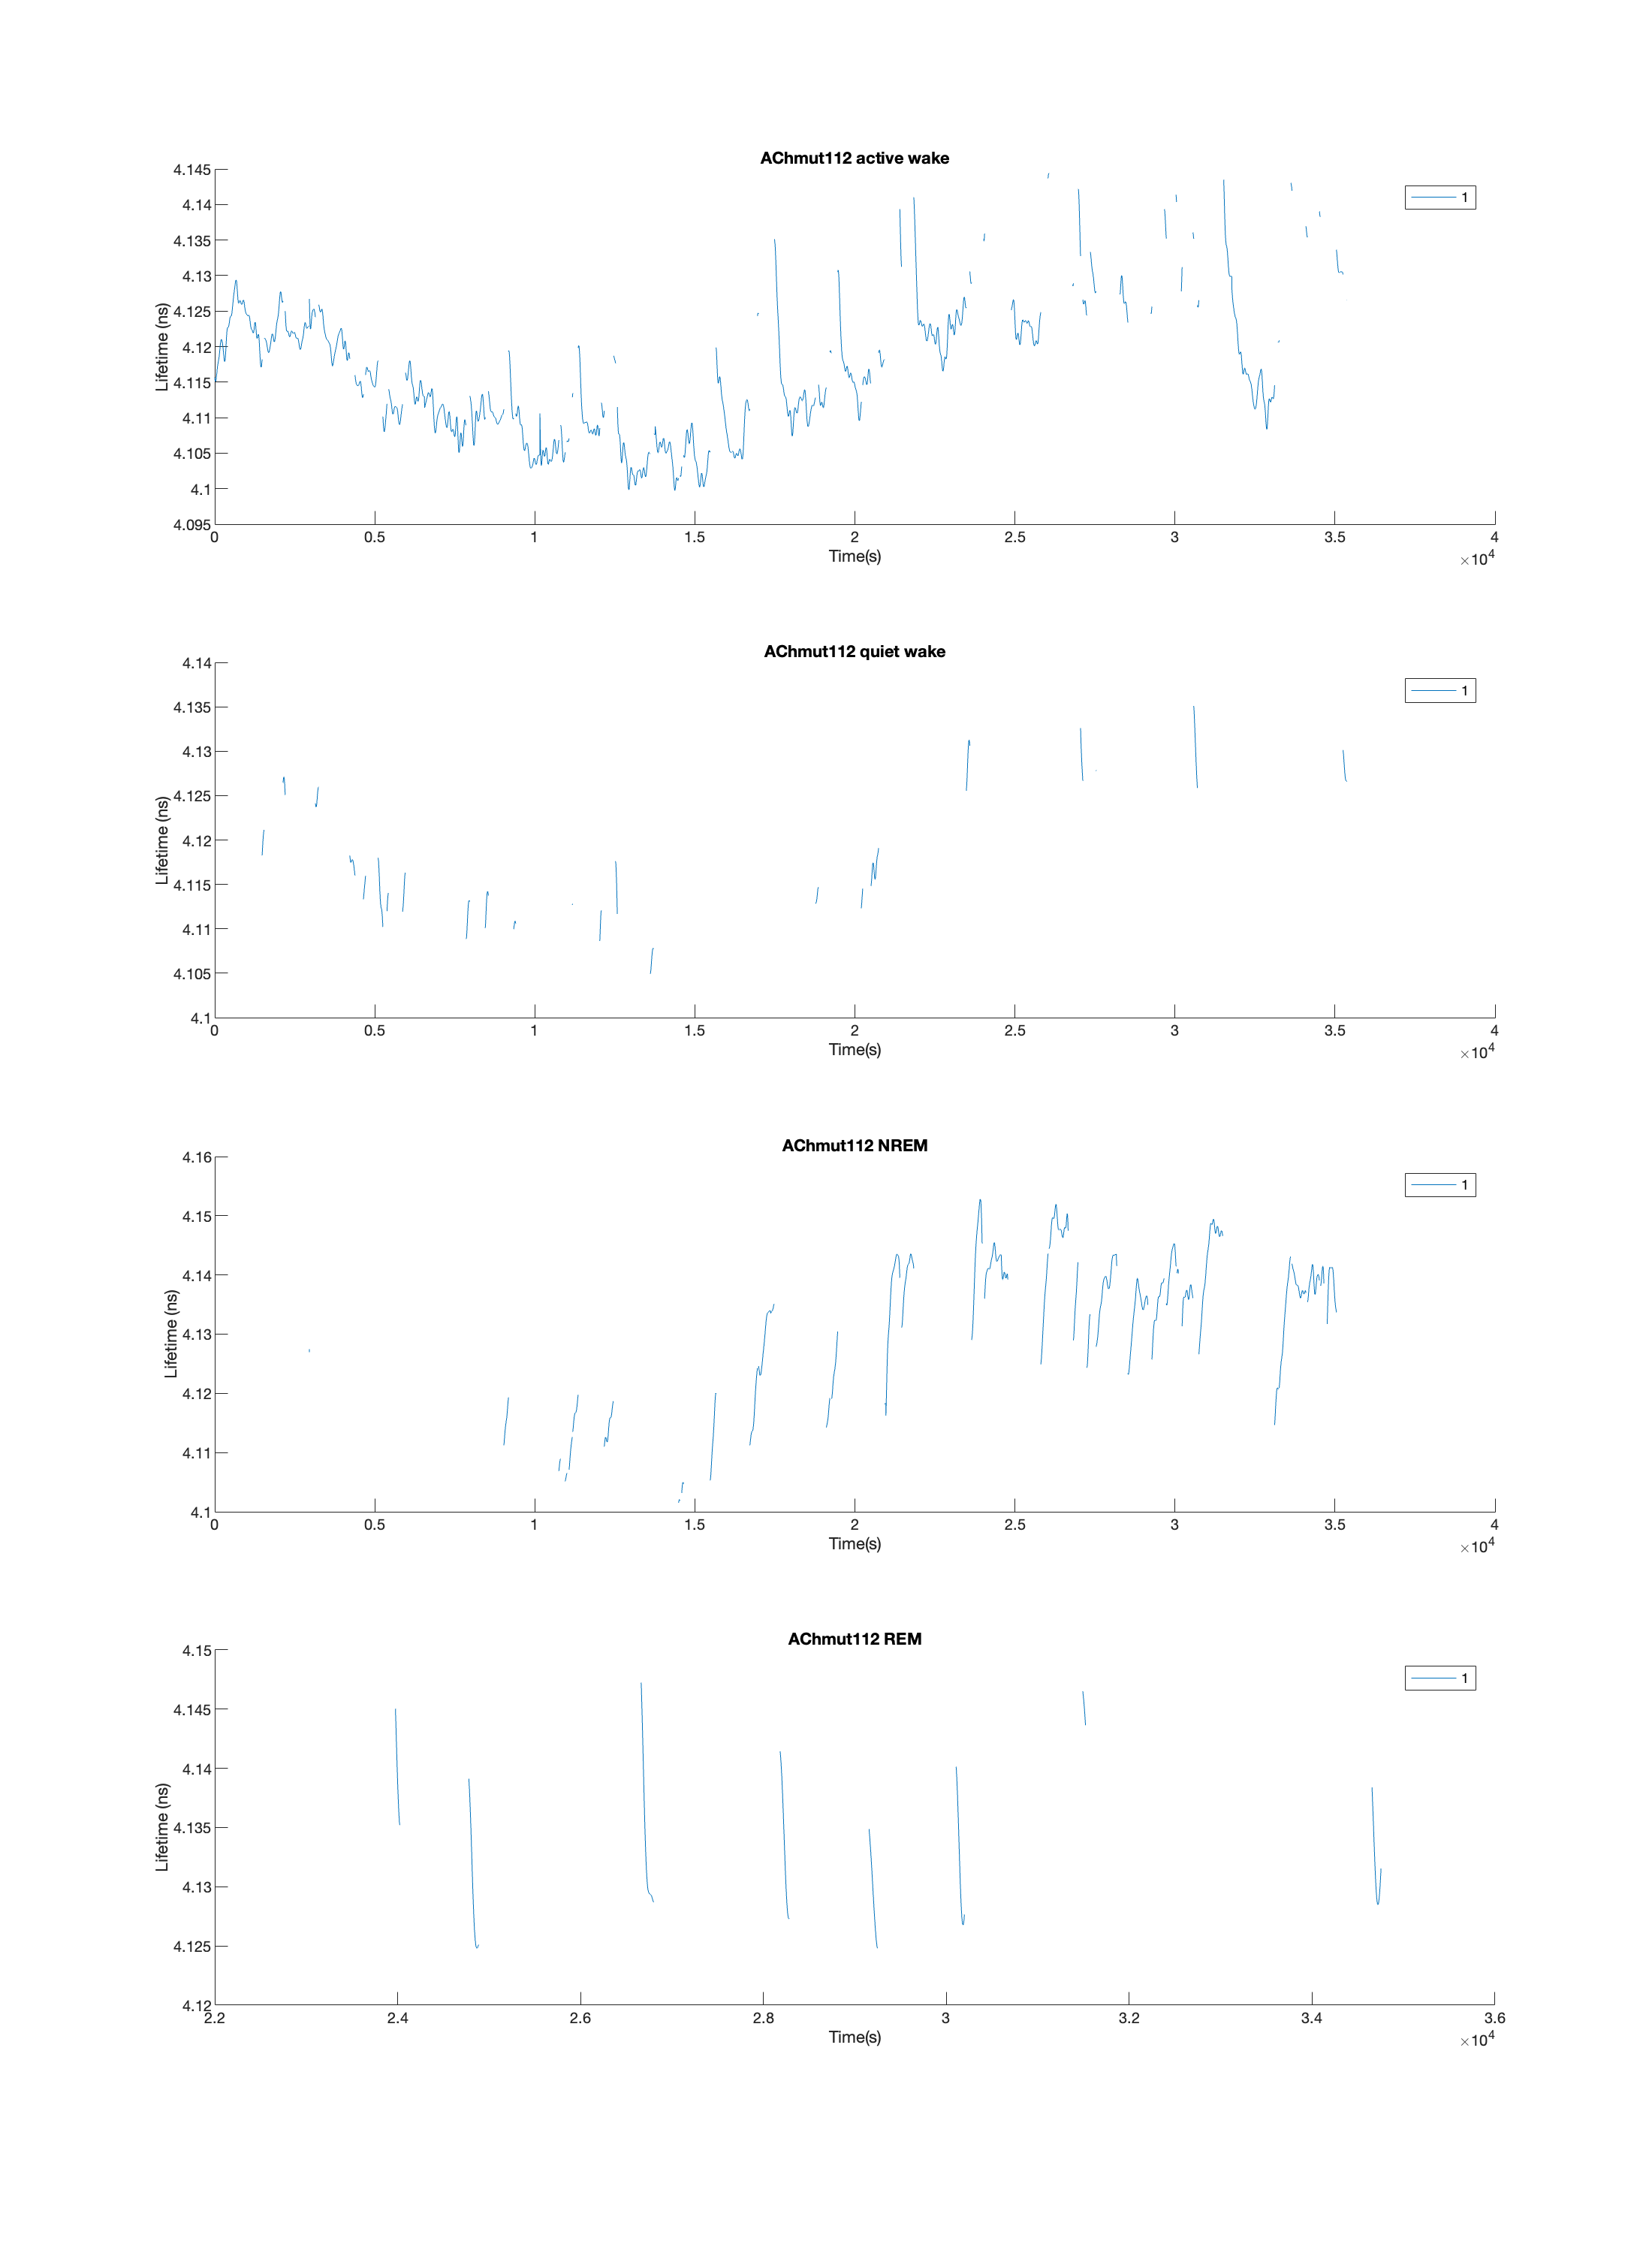

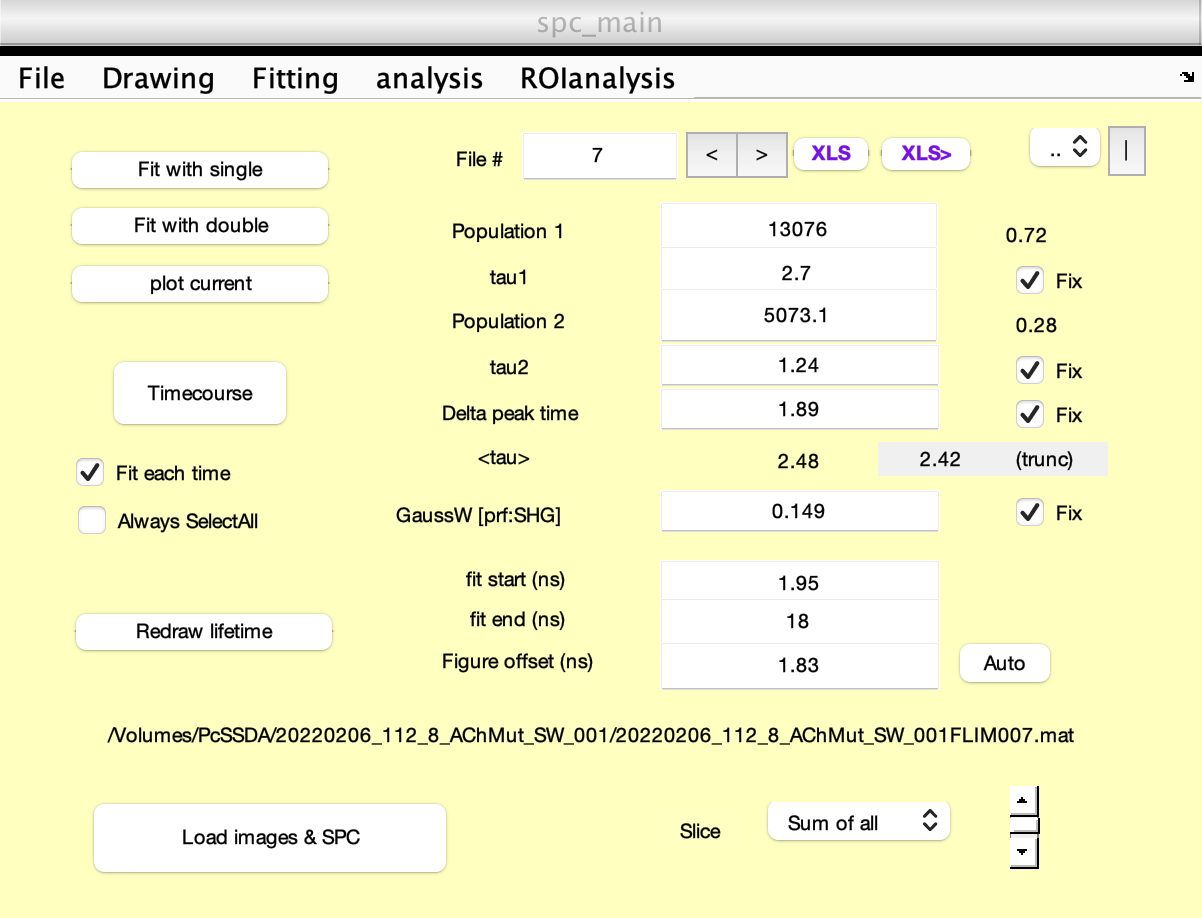

Loading wave object  ...
Loading wave object  ...
Loading wave object  ...


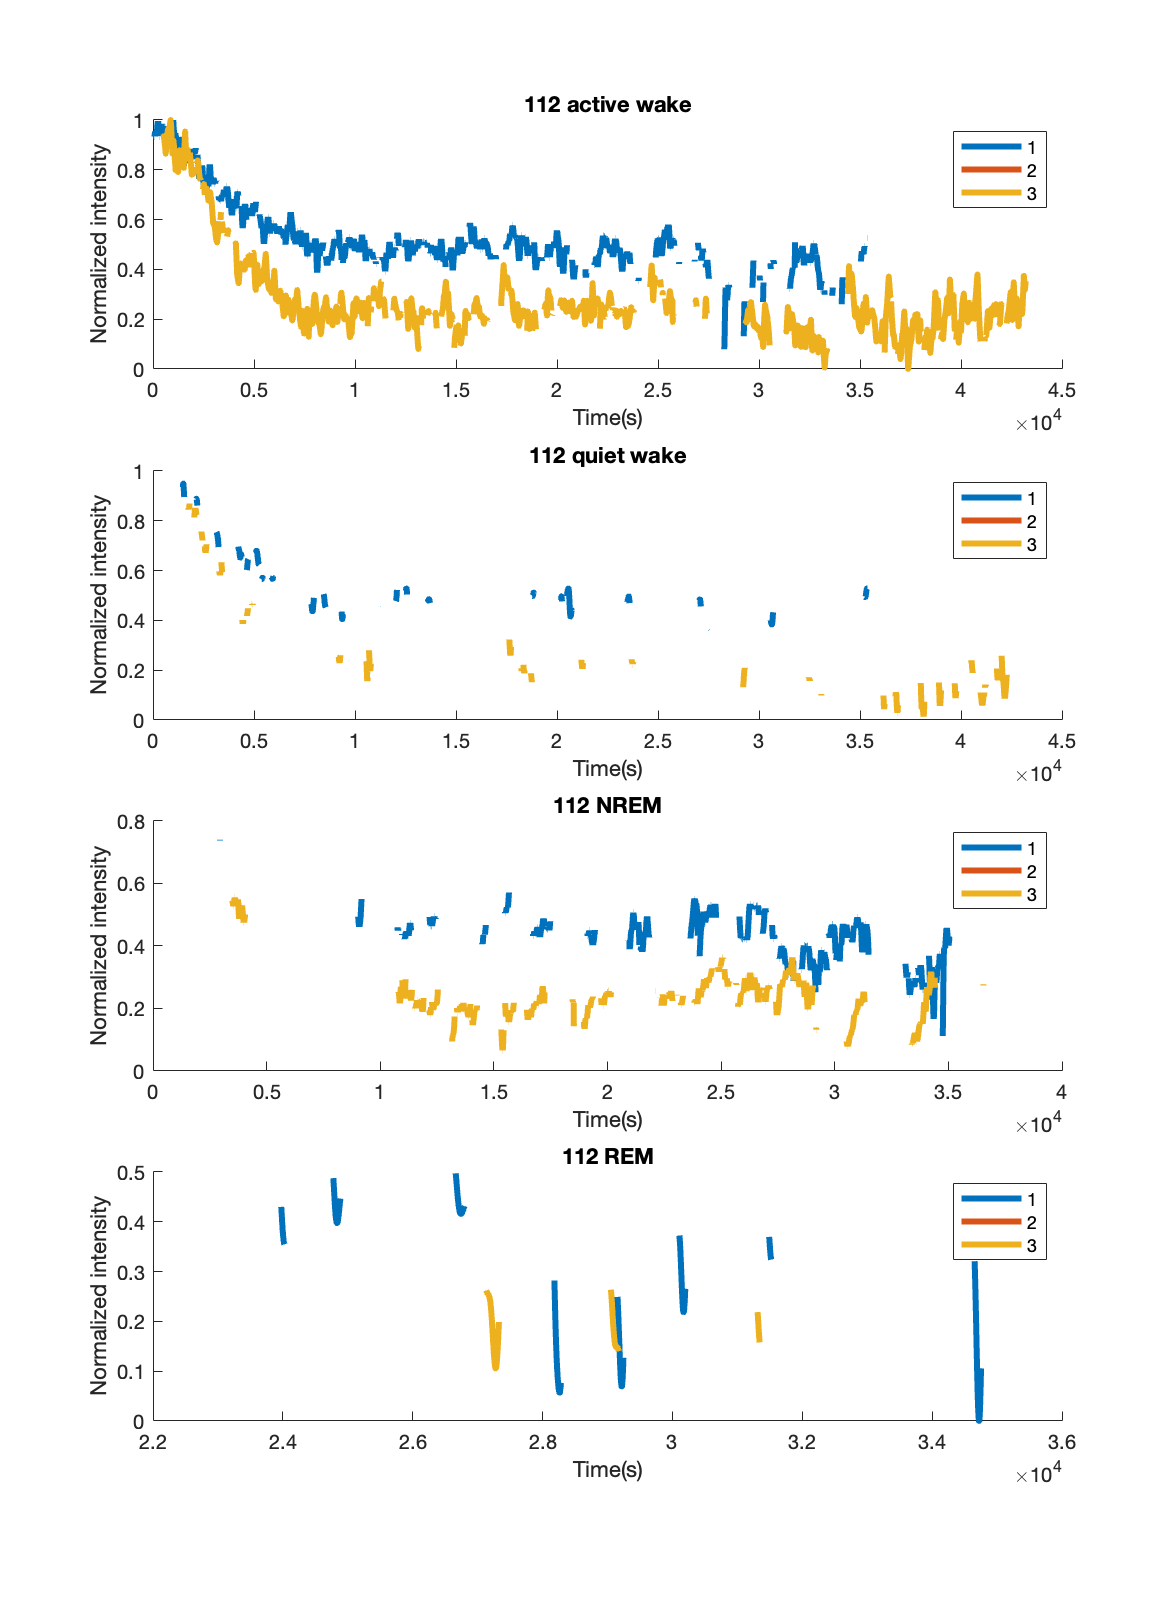

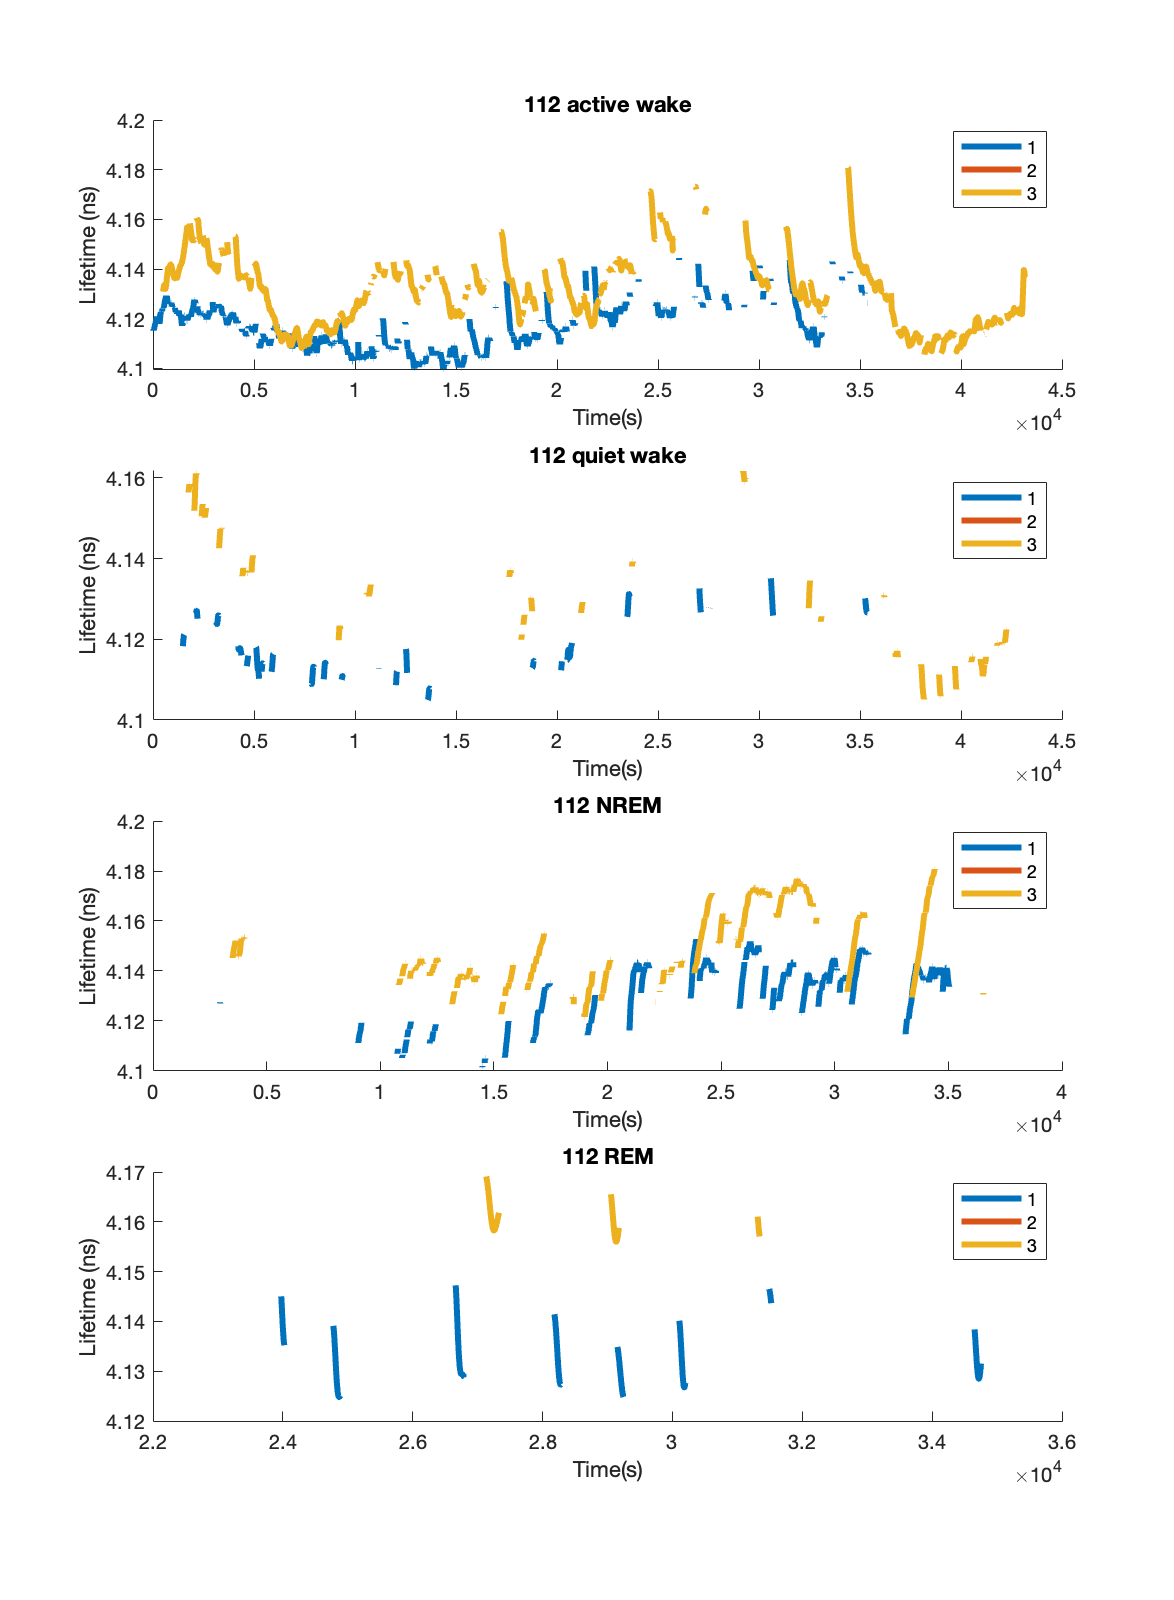

Loading wave object  ...
Loading wave object  ...
Loading wave object  ...


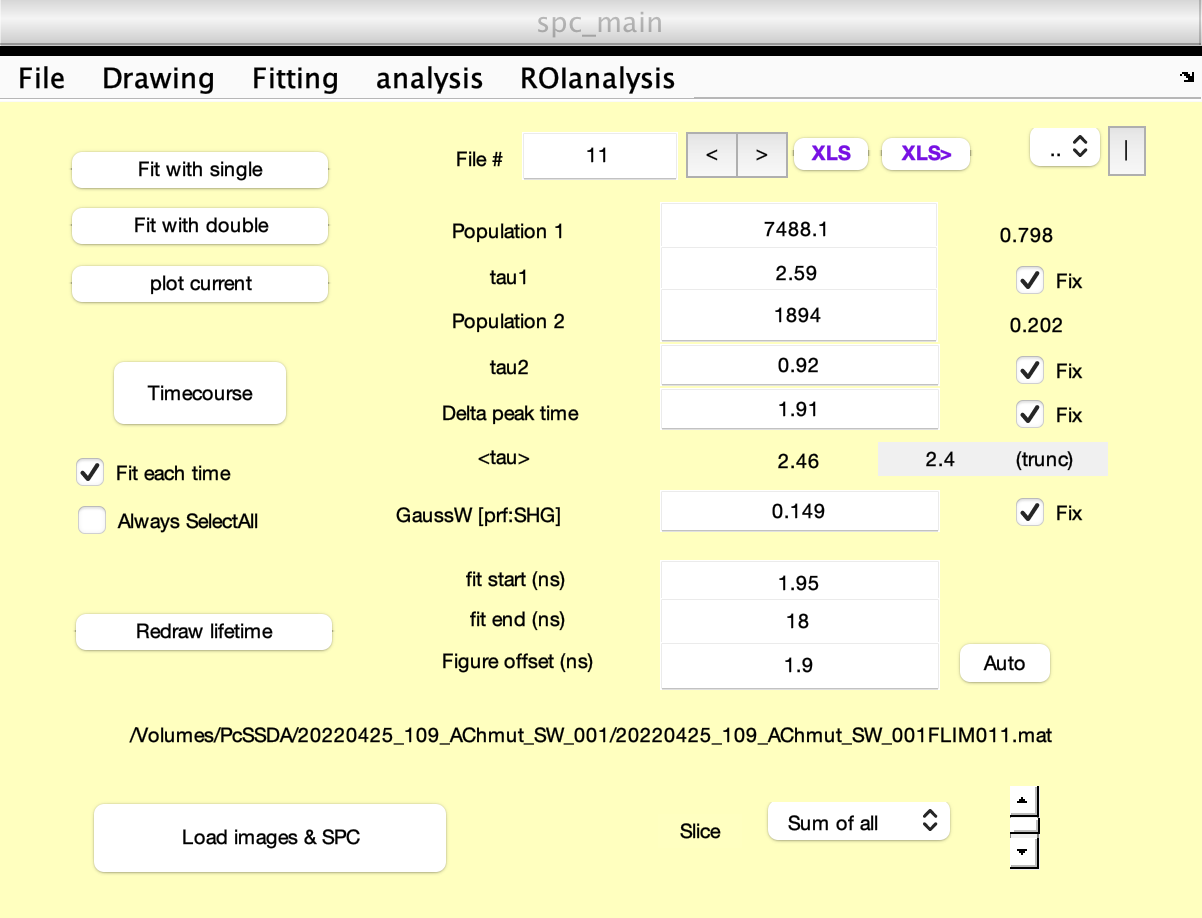

Loading wave object  ...
Loading wave object  ...
Loading wave object  ...


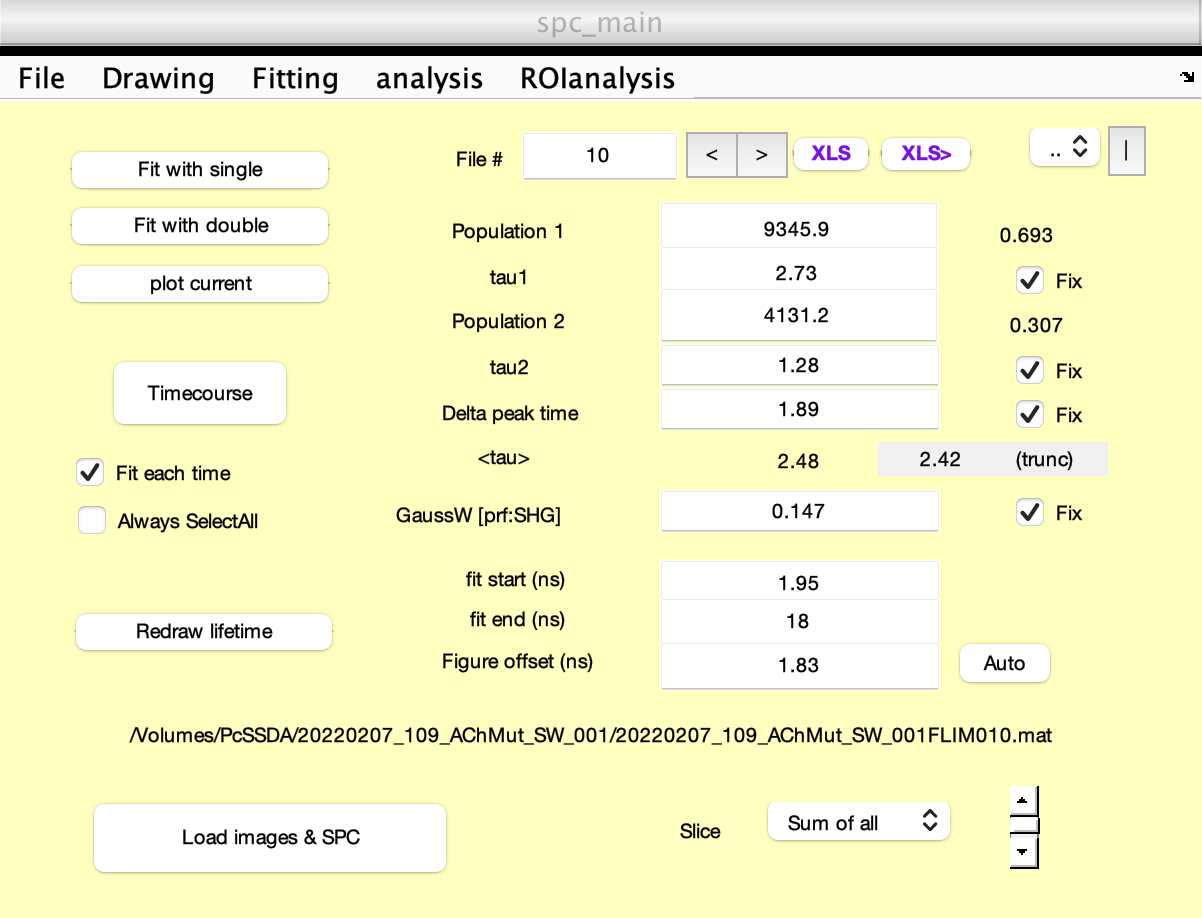

Loading wave object  ...
Loading wave object  ...
Loading wave object  ...


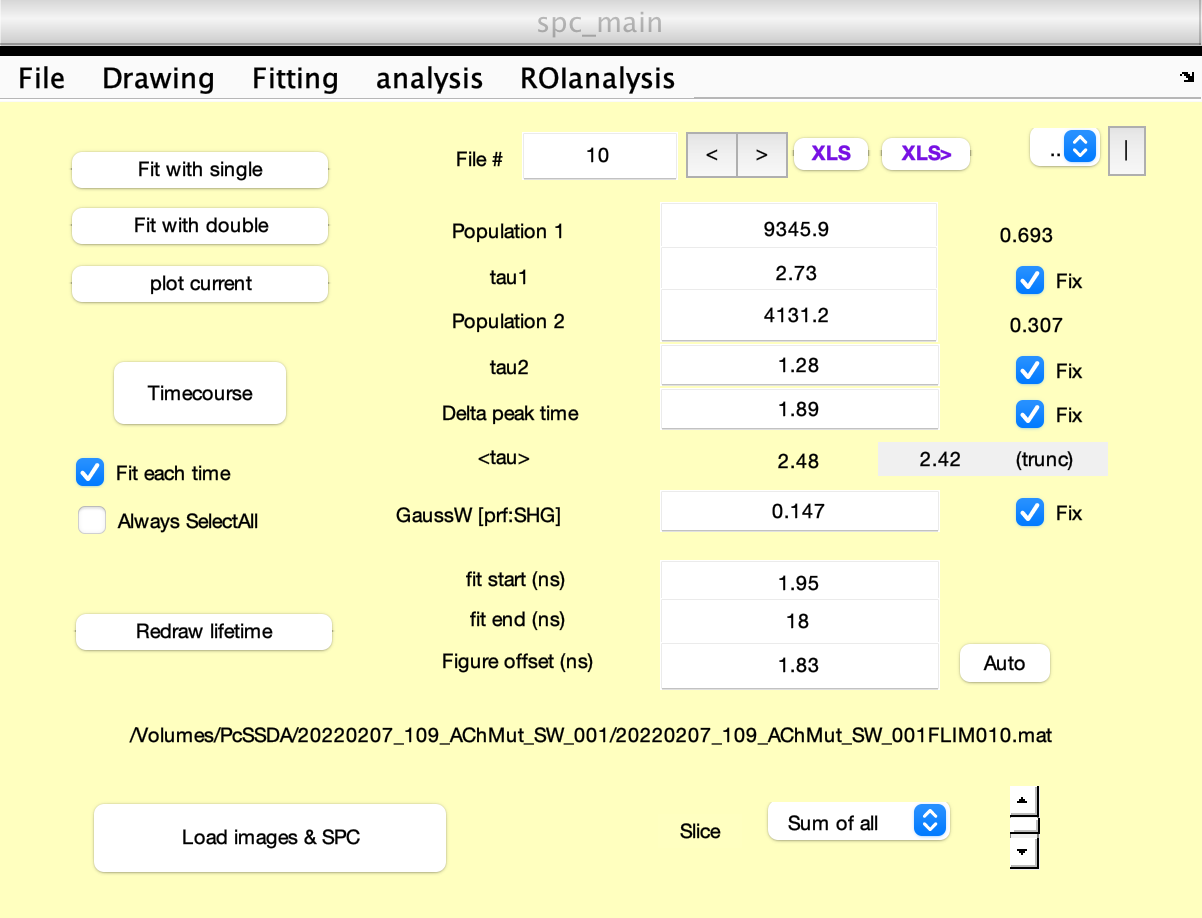

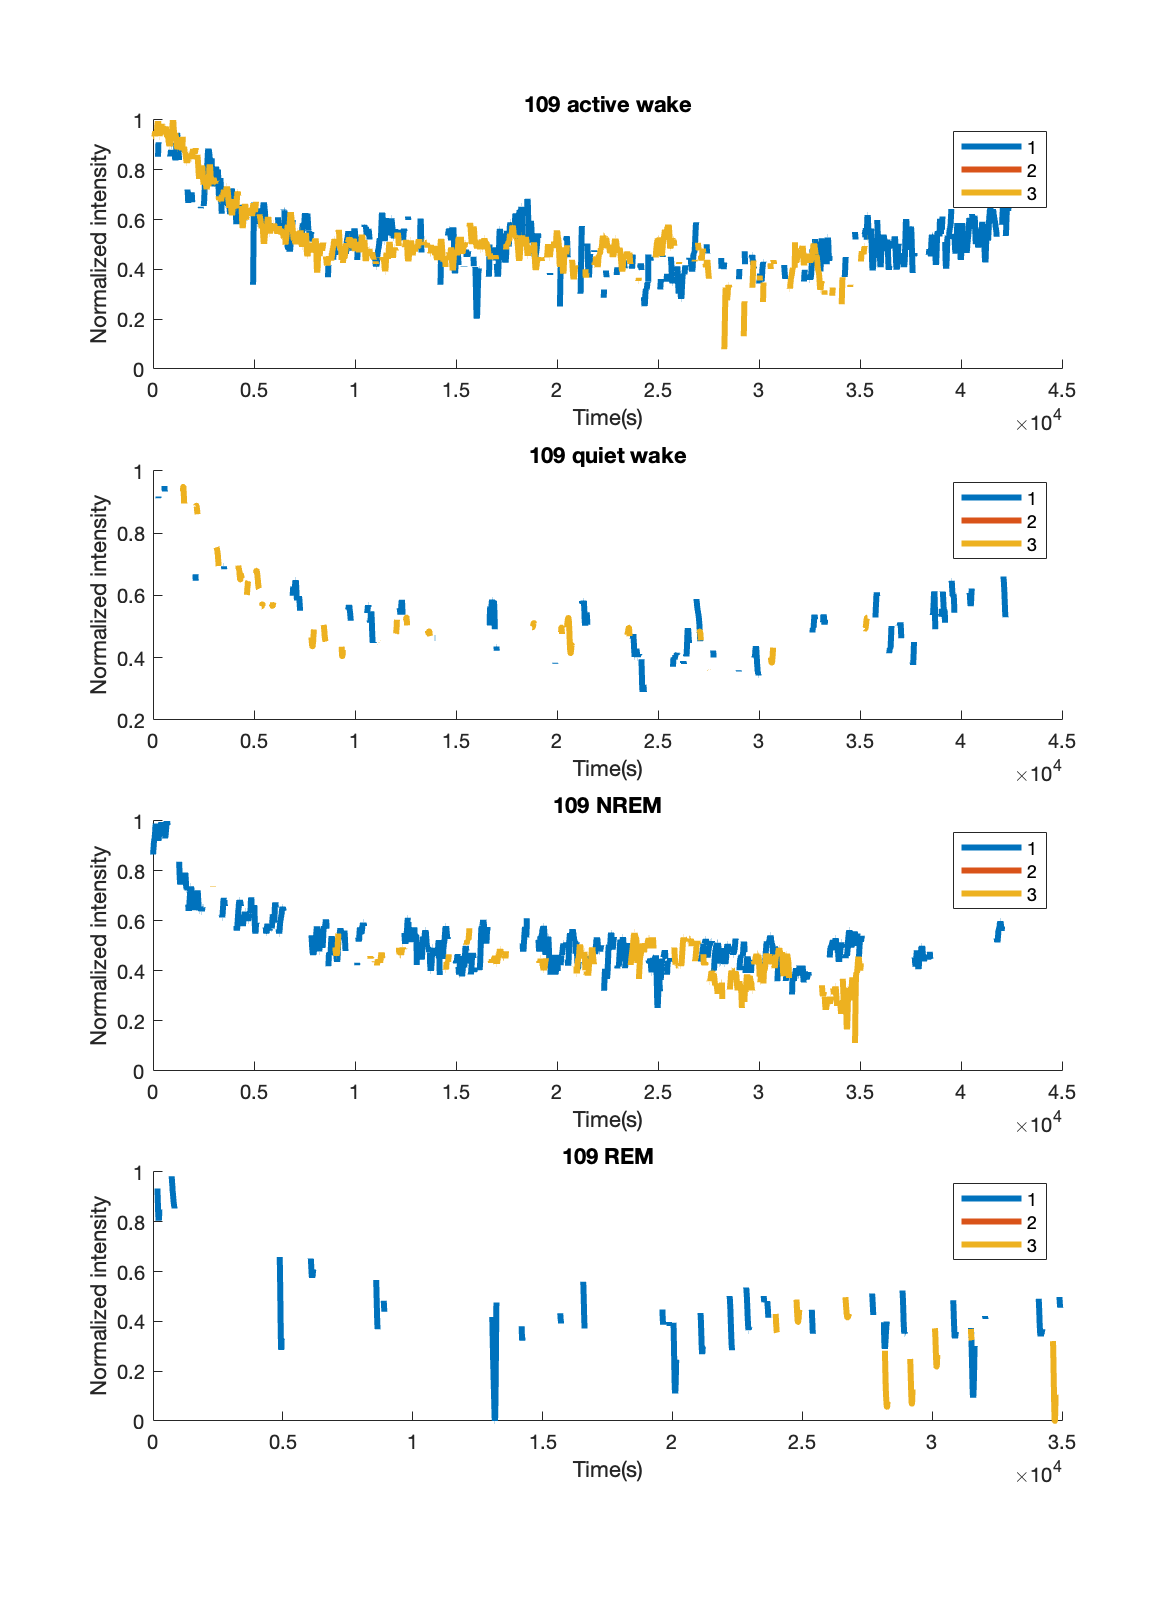

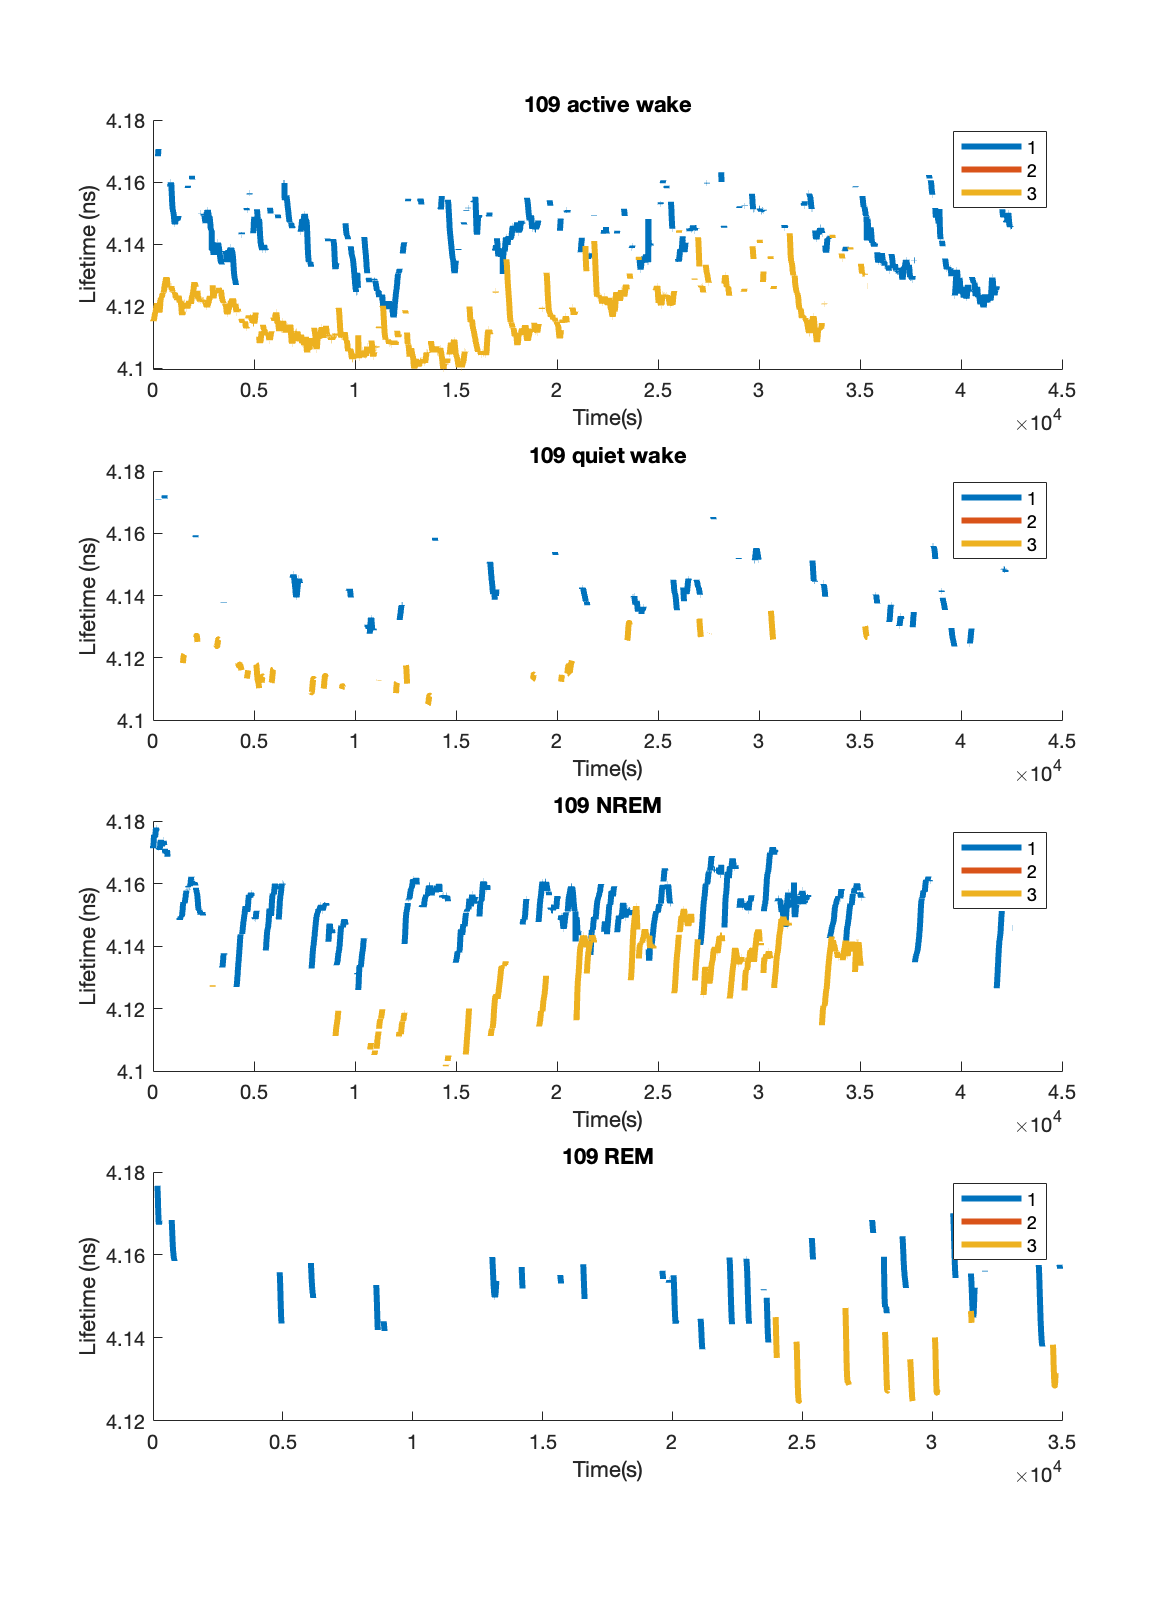


for ii=8:9
    eval(['lft_avgs_AW',num2str(animal_IDs{ii}),'=zeros(3,24);'])
    eval(['lft_avgs_QW',num2str(animal_IDs{ii}),'=zeros(3,24);'])
    eval(['lft_avgs_NREM',num2str(animal_IDs{ii}),'=zeros(3,24);'])
    eval(['lft_avgs_REM',num2str(animal_IDs{ii}),'=zeros(3,24);'])

    cd(data_paths{3*ii-2})
    load("FLP_analysis.mat")

    t1=time_z_all_darkonly;
    intensity_all_darkonly=(intensity_all_darkonly-min(intensity_all_darkonly))/range(intensity_all_darkonly);

    AW_states1=find(states_for_time_all_dark==1);
    QW_states1=find(states_for_time_all_dark==4);
    NREM_states1=find(states_for_time_all_dark==2);
    REM_states1=find(states_for_time_all_dark==3);
                                
    AW_tau1=NaN(size(tau_empTrunc_all_darkonly,1),1);
    QW_tau1=NaN(size(tau_empTrunc_all_darkonly,1),1);
    NREM_tau1=NaN(size(tau_empTrunc_all_darkonly,1),1);
    REM_tau1=NaN(size(tau_empTrunc_all_darkonly,1),1);

    AW_intensity1=NaN(size(tau_empTrunc_all_darkonly,1),1);
    QW_intensity1=NaN(size(tau_empTrunc_all_darkonly,1),1);
    NREM_intensity1=NaN(size(tau_empTrunc_all_darkonly,1),1);
    REM_intensity1=NaN(size(tau_empTrunc_all_darkonly,1),1);

    

    for i=1:size(AW_states1,1)
    AW_tau1(AW_states1(i))=tau_empTrunc_all_darkonly(AW_states1(i));
    AW_intensity1(AW_states1(i))=intensity_all_darkonly(AW_states1(i));
    end

    for i=1:size(QW_states1,1)
        QW_tau1(QW_states1(i))=tau_empTrunc_all_darkonly(QW_states1(i));
        QW_intensity1(QW_states1(i))=intensity_all_darkonly(QW_states1(i));
    end

    for i=1:size(NREM_states1,1)
        NREM_tau1(NREM_states1(i))=tau_empTrunc_all_darkonly(NREM_states1(i));
        NREM_intensity1(NREM_states1(i))=intensity_all_darkonly(NREM_states1(i));
    end

    for i=1:size(REM_states1,1)
        REM_tau1(REM_states1(i))=tau_empTrunc_all_darkonly(REM_states1(i));
        REM_intensity1(REM_states1(i))=intensity_all_darkonly(REM_states1(i));
    end



    cd(data_paths{3*ii-1})
    load("FLP_analysis.mat")

    t2=time_z_all_darkonly;
    intensity_all_darkonly=(intensity_all_darkonly-min(intensity_all_darkonly))/range(intensity_all_darkonly);

    AW_states2=find(states_for_time_all_dark==1);
    QW_states2=find(states_for_time_all_dark==4);
    NREM_states2=find(states_for_time_all_dark==2);
    REM_states2=find(states_for_time_all_dark==3);
                                
    AW_tau2=NaN(size(tau_empTrunc_all_darkonly,1),1);
    QW_tau2=NaN(size(tau_empTrunc_all_darkonly,1),1);
    NREM_tau2=NaN(size(tau_empTrunc_all_darkonly,1),1);
    REM_tau2=NaN(size(tau_empTrunc_all_darkonly,1),1);

    AW_intensity2=NaN(size(tau_empTrunc_all_darkonly,1),1);
    QW_intensity2=NaN(size(tau_empTrunc_all_darkonly,1),1);
    NREM_intensity2=NaN(size(tau_empTrunc_all_darkonly,1),1);
    REM_intensity2=NaN(size(tau_empTrunc_all_darkonly,1),1);

    for i=1:size(AW_states2,1)
    AW_tau2(AW_states2(i))=tau_empTrunc_all_darkonly(AW_states2(i));
    AW_intensity2(AW_states2(i))=intensity_all_darkonly(AW_states2(i));
    end

    for i=1:size(QW_states2,1)
        QW_tau2(QW_states2(i))=tau_empTrunc_all_darkonly(QW_states2(i));
        QW_intensity2(QW_states2(i))=intensity_all_darkonly(QW_states2(i));
    end

    for i=1:size(NREM_states2,1)
        NREM_tau2(NREM_states2(i))=tau_empTrunc_all_darkonly(NREM_states2(i));
        NREM_intensity2(NREM_states2(i))=intensity_all_darkonly(NREM_states2(i));
    end

    for i=1:size(REM_states2,1)
        REM_tau2(REM_states2(i))=tau_empTrunc_all_darkonly(REM_states2(i));
        REM_intensity2(REM_states2(i))=intensity_all_darkonly(REM_states2(i));
    end

    cd(data_paths{3*ii})
    load("FLP_analysis.mat")

    t3=time_z_all_darkonly;
    intensity_all_darkonly=(intensity_all_darkonly-min(intensity_all_darkonly))/range(intensity_all_darkonly);

    AW_states3=find(states_for_time_all_dark==1);
    QW_states3=find(states_for_time_all_dark==4);
    NREM_states3=find(states_for_time_all_dark==2);
    REM_states3=find(states_for_time_all_dark==3);
                                
    AW_tau3=NaN(size(tau_empTrunc_all_darkonly,1),1);
    QW_tau3=NaN(size(tau_empTrunc_all_darkonly,1),1);
    NREM_tau3=NaN(size(tau_empTrunc_all_darkonly,1),1);
    REM_tau3=NaN(size(tau_empTrunc_all_darkonly,1),1);

    AW_intensity3=NaN(size(tau_empTrunc_all_darkonly,1),1);
    QW_intensity3=NaN(size(tau_empTrunc_all_darkonly,1),1);
    NREM_intensity3=NaN(size(tau_empTrunc_all_darkonly,1),1);
    REM_intensity3=NaN(size(tau_empTrunc_all_darkonly,1),1);

    for i=1:size(AW_states3,1)
    AW_tau3(AW_states3(i))=tau_empTrunc_all_darkonly(AW_states3(i));
    AW_intensity3(AW_states3(i))=intensity_all_darkonly(AW_states3(i));
    end

    for i=1:size(QW_states3,1)
        QW_tau3(QW_states3(i))=tau_empTrunc_all_darkonly(QW_states3(i));
        QW_intensity3(QW_states3(i))=intensity_all_darkonly(QW_states3(i));
    end

    for i=1:size(NREM_states3,1)
        NREM_tau3(NREM_states3(i))=tau_empTrunc_all_darkonly(NREM_states3(i));
        NREM_intensity3(NREM_states3(i))=intensity_all_darkonly(NREM_states3(i));
    end

    for i=1:size(REM_states3,1)
        REM_tau3(REM_states3(i))=tau_empTrunc_all_darkonly(REM_states3(i));
        REM_intensity3(REM_states3(i))=intensity_all_darkonly(REM_states3(i));
    end

    figure1=figure;
    figure1.Position=[10 10 1100 1500];

    CR_plot1=subplot(4,1,1,'Parent',figure1);
    hold(CR_plot1,'on')
    plot(t1, AW_intensity1,'LineWidth',3)
    plot(t2, AW_intensity2,'LineWidth',3)
    plot(t3, AW_intensity3,'LineWidth',3)
    legend('1','2','3')
    title([animal_IDs{ii}, ' active wake'])
    ylabel('Normalized intensity')
    xlabel('Time(s)')
    hold(CR_plot1,'off')

    CR_plot2=subplot(4,1,2,'Parent',figure1);
    hold(CR_plot2,'on')
    plot(t1, QW_intensity1,'LineWidth',3)
    plot(t2, QW_intensity2,'LineWidth',3)
    plot(t3, QW_intensity3,'LineWidth',3)
    legend('1','2','3')
    title([animal_IDs{ii}, ' quiet wake'])
    ylabel('Normalized intensity')
    xlabel('Time(s)')
    hold(CR_plot2,'off')

    CR_plot3=subplot(4,1,3,'Parent',figure1);
    hold(CR_plot3,'on')
    plot(t1, NREM_intensity1,'LineWidth',3)
    plot(t2, NREM_intensity2,'LineWidth',3)
    plot(t3, NREM_intensity3,'LineWidth',3)
    legend('1','2','3')
    title([animal_IDs{ii}, ' NREM'])
    ylabel('Normalized intensity')
    xlabel('Time(s)')
    hold(CR_plot3,'off')

    CR_plot4=subplot(4,1,4,'Parent',figure1);
    hold(CR_plot4,'on')
    plot(t1, REM_intensity1,'LineWidth',3)
    plot(t2, REM_intensity2,'LineWidth',3)
    plot(t3, REM_intensity3,'LineWidth',3)
    legend('1','2','3')
    title([animal_IDs{ii}, ' REM'])
    ylabel('Normalized intensity')
    xlabel('Time(s)')
    hold(CR_plot4,'off')

    saveas(figure1, ['/Volumes/PcSSDA/',animal_IDs{ii},'_intensity_CR_DC.png'])

    figure2=figure;
    figure2.Position=[10 10 1100 1500];

    CR_plot1=subplot(4,1,1,'Parent',figure2);
    hold(CR_plot1,'on')
    plot(t1, AW_tau1,'LineWidth',3)
    plot(t2, AW_tau2,'LineWidth',3)
    plot(t3, AW_tau3,'LineWidth',3)
    legend('1','2','3')
    title([animal_IDs{ii}, ' active wake'])
    ylabel('Lifetime (ns)')
    xlabel('Time(s)')
    hold(CR_plot1,'off')

    CR_plot2=subplot(4,1,2,'Parent',figure2);
    hold(CR_plot2,'on')
    plot(t1, QW_tau1,'LineWidth',3)
    plot(t2, QW_tau2,'LineWidth',3)
    plot(t3, QW_tau3,'LineWidth',3)
    legend('1','2','3')
    title([animal_IDs{ii}, ' quiet wake'])
    ylabel('Lifetime (ns)')
    xlabel('Time(s)')
    hold(CR_plot2,'off')

    CR_plot3=subplot(4,1,3,'Parent',figure2);
    hold(CR_plot3,'on')
    plot(t1, NREM_tau1,'LineWidth',3)
    plot(t2, NREM_tau2,'LineWidth',3)
    plot(t3, NREM_tau3,'LineWidth',3)
    legend('1','2','3')
    title([animal_IDs{ii}, ' NREM'])
    ylabel('Lifetime (ns)')
    xlabel('Time(s)')
    hold(CR_plot3,'off')

    CR_plot4=subplot(4,1,4,'Parent',figure2);
    hold(CR_plot4,'on')
    plot(t1, REM_tau1,'LineWidth',3)
    plot(t2, REM_tau2,'LineWidth',3)
    plot(t3, REM_tau3,'LineWidth',3)
    legend('1','2','3')
    title([animal_IDs{ii}, ' REM'])
    ylabel('Lifetime (ns)')
    xlabel('Time(s)')
    hold(CR_plot4,'off')

    saveas(figure2, ['/Volumes/PcSSDA/',animal_IDs{ii},'_lft_CR_DC.png'])

    
end

Loading wave object  ...
Loading wave object  ...
Loading wave object  ...


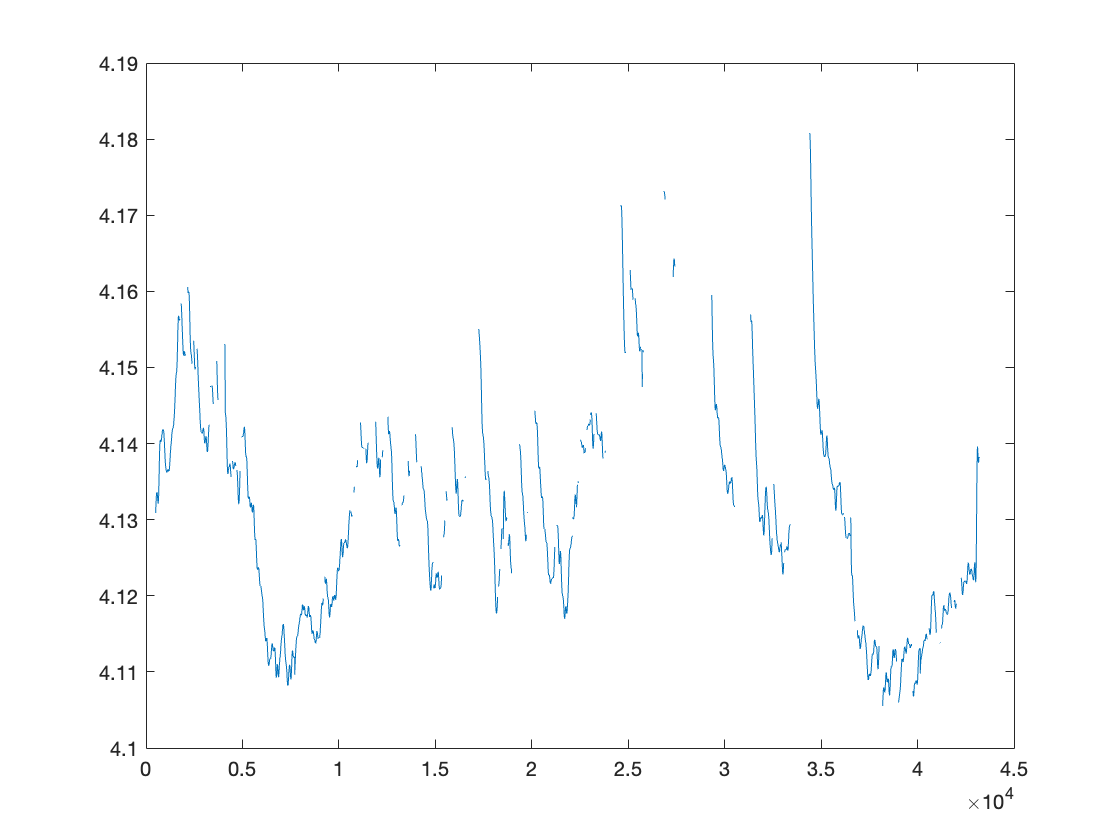

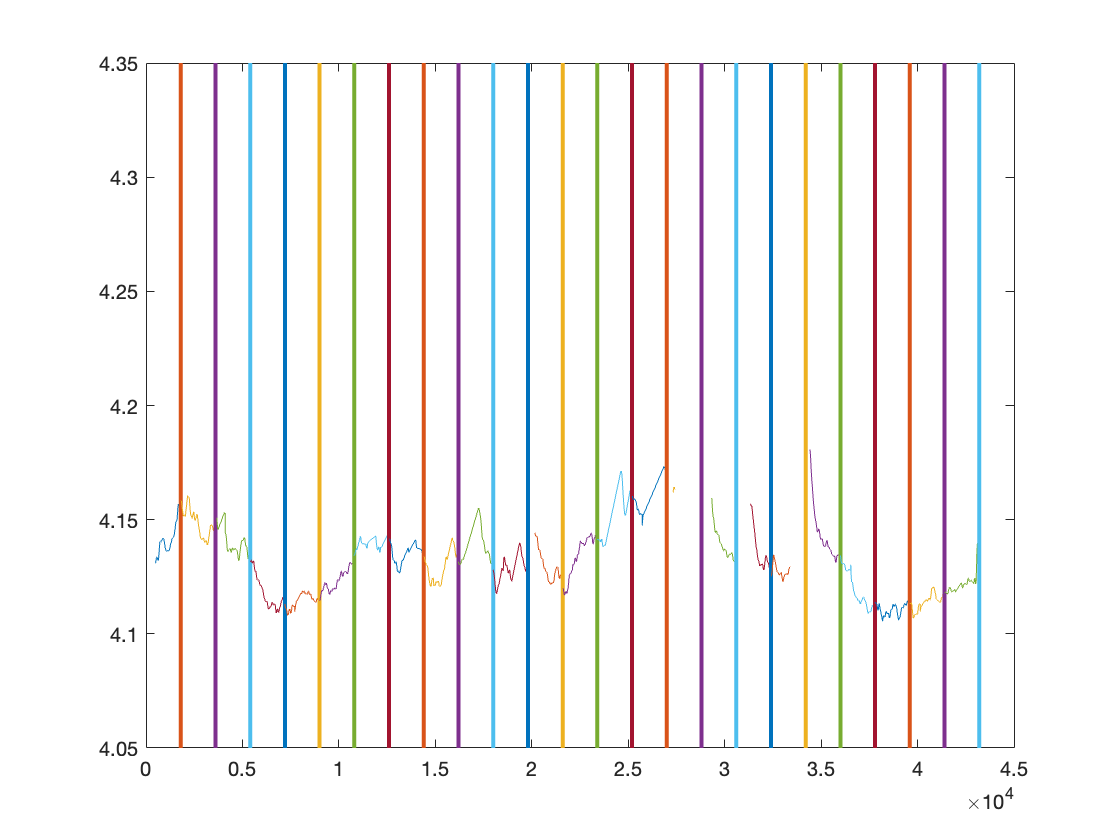

Loading wave object  ...
Loading wave object  ...
Loading wave object  ...


Loading wave object  ...
Loading wave object  ...
Loading wave object  ...


Loading wave object  ...
Loading wave object  ...
Loading wave object  ...


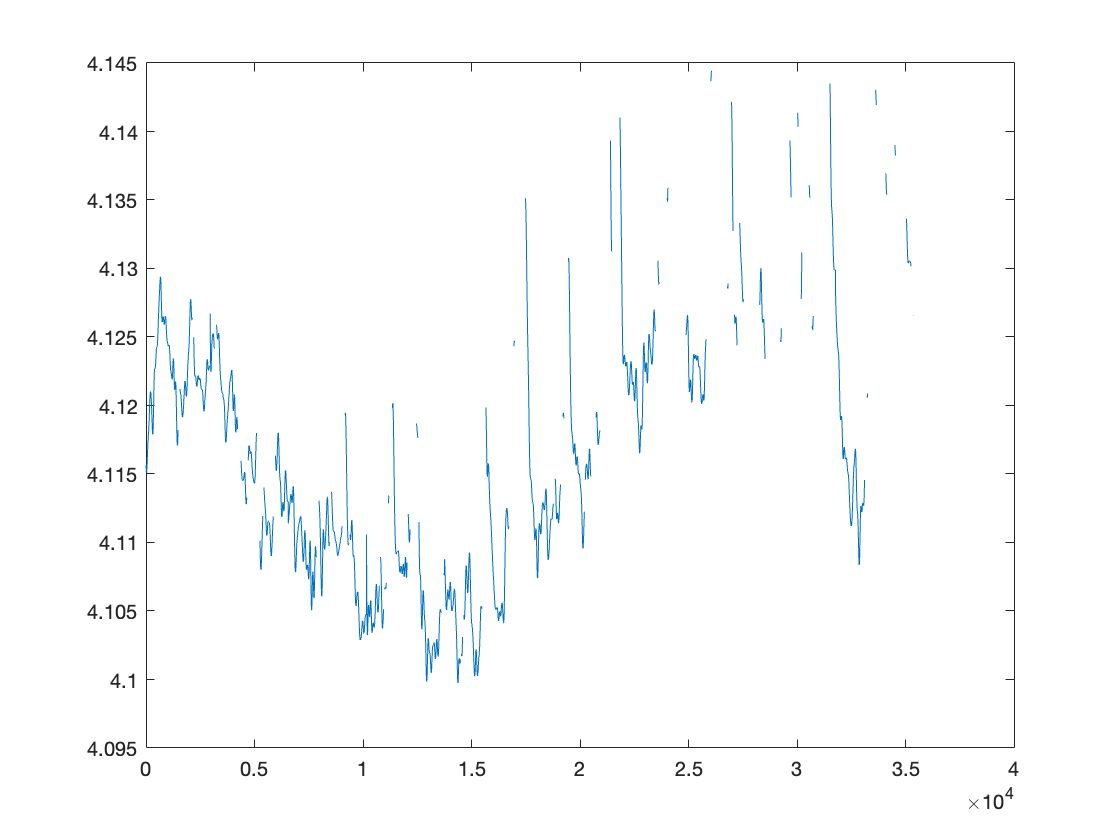

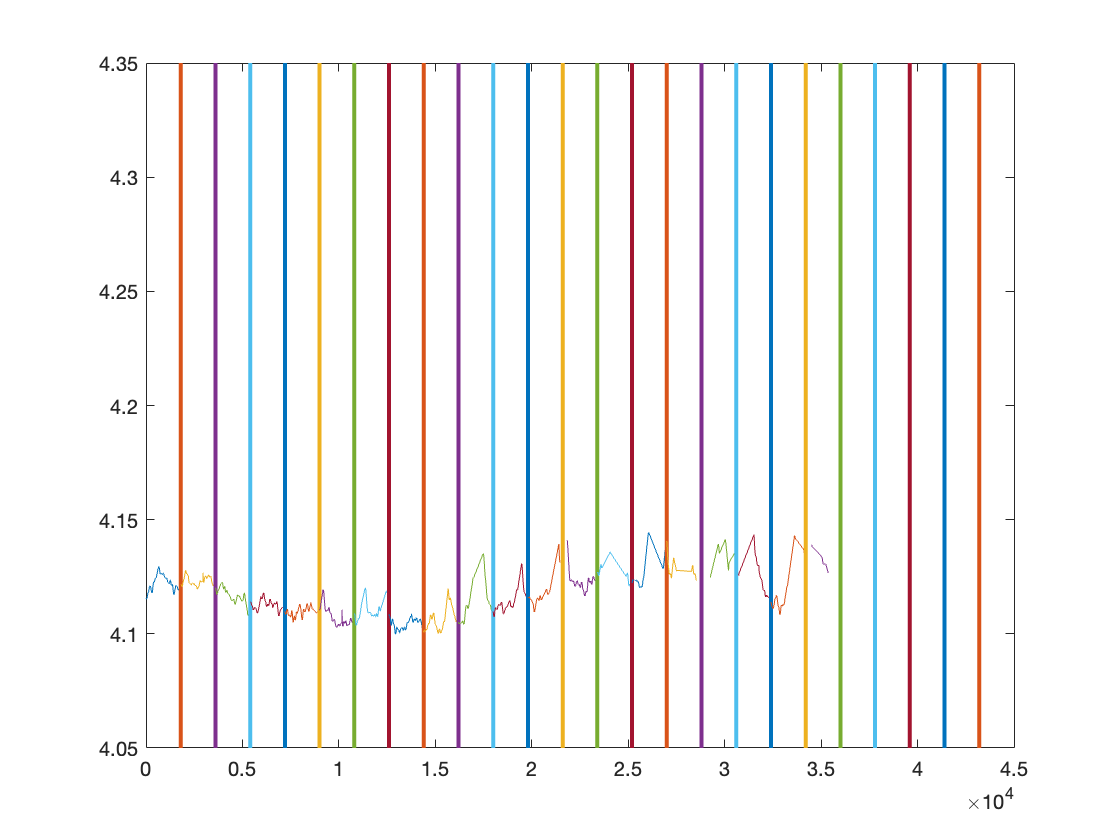

Loading wave object  ...
Loading wave object  ...
Loading wave object  ...


lft_avg_all_AW=[];
lft_avg_all_QW=[];
lft_avg_all_NREM=[];
lft_avg_all_REM=[];

intensity_avg_all_AW=[];
intensity_avg_all_QW=[];
intensity_avg_all_NREM=[];
intensity_avg_all_REM=[];


CR_time=(0:1:23)*1800+900;

for ii=8:9
    eval(['lft_avgs_AW_',num2str(animal_IDs{ii}),'=NaN(3,24);'])
    eval(['lft_avgs_QW_',num2str(animal_IDs{ii}),'=NaN(3,24);'])
    eval(['lft_avgs_NREM_',num2str(animal_IDs{ii}),'=NaN(3,24);'])
    eval(['lft_avgs_REM_',num2str(animal_IDs{ii}),'=NaN(3,24);'])

    eval(['intensity_avgs_AW_',num2str(animal_IDs{ii}),'=NaN(3,24);'])
    eval(['intensity_avgs_QW_',num2str(animal_IDs{ii}),'=NaN(3,24);'])
    eval(['intensity_avgs_NREM_',num2str(animal_IDs{ii}),'=NaN(3,24);'])
    eval(['intensity_avgs_REM_',num2str(animal_IDs{ii}),'=NaN(3,24);'])

    cd(data_paths{3*ii-2})
    load("FLP_analysis.mat")

    t1=time_z_all_darkonly;
    intensity_all_darkonly=(intensity_all_darkonly-min(intensity_all_darkonly))/range(intensity_all_darkonly);

    AW_states1=find(states_for_time_all_dark==1);
    QW_states1=find(states_for_time_all_dark==4);
    NREM_states1=find(states_for_time_all_dark==2);
    REM_states1=find(states_for_time_all_dark==3);
                                
    AW_tau1=NaN(size(tau_empTrunc_all_darkonly,1),1);
    QW_tau1=NaN(size(tau_empTrunc_all_darkonly,1),1);
    NREM_tau1=NaN(size(tau_empTrunc_all_darkonly,1),1);
    REM_tau1=NaN(size(tau_empTrunc_all_darkonly,1),1);

    AW_t1=NaN(size(tau_empTrunc_all_darkonly,1),1);
    QW_t1=NaN(size(tau_empTrunc_all_darkonly,1),1);
    NREM_t1=NaN(size(tau_empTrunc_all_darkonly,1),1);
    REM_t1=NaN(size(tau_empTrunc_all_darkonly,1),1);

    AW_intensity1=NaN(size(tau_empTrunc_all_darkonly,1),1);
    QW_intensity1=NaN(size(tau_empTrunc_all_darkonly,1),1);
    NREM_intensity1=NaN(size(tau_empTrunc_all_darkonly,1),1);
    REM_intensity1=NaN(size(tau_empTrunc_all_darkonly,1),1);

    

    for i=1:size(AW_states1,1)
       AW_tau1(AW_states1(i))=tau_empTrunc_all_darkonly(AW_states1(i));
       AW_intensity1(AW_states1(i))=intensity_all_darkonly(AW_states1(i));
       AW_t1(AW_states1(i))=t1(AW_states1(i));
    end

    for i=1:size(QW_states1,1)
        QW_tau1(QW_states1(i))=tau_empTrunc_all_darkonly(QW_states1(i));
        QW_intensity1(QW_states1(i))=intensity_all_darkonly(QW_states1(i));
        QW_t1(QW_states1(i))=t1(QW_states1(i));
    end

    for i=1:size(NREM_states1,1)
        NREM_tau1(NREM_states1(i))=tau_empTrunc_all_darkonly(NREM_states1(i));
        NREM_intensity1(NREM_states1(i))=intensity_all_darkonly(NREM_states1(i));
        NREM_t1(NREM_states1(i))=t1(NREM_states1(i));
    end

    for i=1:size(REM_states1,1)
        REM_tau1(REM_states1(i))=tau_empTrunc_all_darkonly(REM_states1(i));
        REM_intensity1(REM_states1(i))=intensity_all_darkonly(REM_states1(i));
        REM_t1(REM_states1(i))=t1(REM_states1(i));
    end

%     figure
%     plot(AW_t1,AW_tau1)
%     
%     figure

    for jj=1:24
        bin_start=1800*(jj-1);
        bin_end=1800*jj;

        this_bin=find(AW_t1>=bin_start & AW_t1<bin_end);
        eval(['lft_avgs_AW_',num2str(animal_IDs{ii}),'(1,jj)=nanmean(AW_tau1(this_bin));'])
        
%         plot(AW_t1(this_bin),AW_tau1(this_bin))
%         hold on
%         plot([bin_end bin_end],[4.05 4.35],'LineWidth',2)
%         hold on
        this_bin=find(QW_t1>=bin_start & QW_t1<bin_end);
        eval(['lft_avgs_QW_',num2str(animal_IDs{ii}),'(1,jj)=nanmean(QW_tau1(this_bin));'])
        this_bin=find(NREM_t1>=bin_start & NREM_t1<bin_end);
        eval(['lft_avgs_NREM_',num2str(animal_IDs{ii}),'(1,jj)=nanmean(NREM_tau1(this_bin));'])
        this_bin=find(REM_t1>=bin_start & REM_t1<bin_end);
        eval(['lft_avgs_REM_',num2str(animal_IDs{ii}),'(1,jj)=nanmean(REM_tau1(this_bin));'])

    end
%     hold off

    for jj=1:24
        bin_start=1800*(jj-1);
        bin_end=1800*jj;

        this_bin=find(AW_t1>=bin_start & AW_t1<bin_end);
        eval(['intensity_avgs_AW_',num2str(animal_IDs{ii}),'(1,jj)=nanmean(AW_intensity1(this_bin));'])
        this_bin=find(QW_t1>=bin_start & QW_t1<bin_end);
        eval(['intensity_avgs_QW_',num2str(animal_IDs{ii}),'(1,jj)=nanmean(QW_intensity1(this_bin));'])
        this_bin=find(NREM_t1>=bin_start & NREM_t1<bin_end);
        eval(['intensity_avgs_NREM_',num2str(animal_IDs{ii}),'(1,jj)=nanmean(NREM_intensity1(this_bin));'])
        this_bin=find(REM_t1>=bin_start & REM_t1<bin_end);
        eval(['intensity_avgs_REM_',num2str(animal_IDs{ii}),'(1,jj)=nanmean(REM_intensity1(this_bin));'])

    end



    cd(data_paths{3*ii-1})
    load("FLP_analysis.mat")

    t2=time_z_all_darkonly;
    intensity_all_darkonly=(intensity_all_darkonly-min(intensity_all_darkonly))/range(intensity_all_darkonly);

    AW_states2=find(states_for_time_all_dark==1);
    QW_states2=find(states_for_time_all_dark==4);
    NREM_states2=find(states_for_time_all_dark==2);
    REM_states2=find(states_for_time_all_dark==3);
                                
    AW_tau2=NaN(size(tau_empTrunc_all_darkonly,1),1);
    QW_tau2=NaN(size(tau_empTrunc_all_darkonly,1),1);
    NREM_tau2=NaN(size(tau_empTrunc_all_darkonly,1),1);
    REM_tau2=NaN(size(tau_empTrunc_all_darkonly,1),1);

    AW_t2=NaN(size(tau_empTrunc_all_darkonly,1),1);
    QW_t2=NaN(size(tau_empTrunc_all_darkonly,1),1);
    NREM_t2=NaN(size(tau_empTrunc_all_darkonly,1),1);
    REM_t2=NaN(size(tau_empTrunc_all_darkonly,1),1);

    AW_intensity2=NaN(size(tau_empTrunc_all_darkonly,1),1);
    QW_intensity2=NaN(size(tau_empTrunc_all_darkonly,1),1);
    NREM_intensity2=NaN(size(tau_empTrunc_all_darkonly,1),1);
    REM_intensity2=NaN(size(tau_empTrunc_all_darkonly,1),1);

    for i=1:size(AW_states2,1)
        AW_tau2(AW_states2(i))=tau_empTrunc_all_darkonly(AW_states2(i));
        AW_intensity2(AW_states2(i))=intensity_all_darkonly(AW_states2(i));
        AW_t2(AW_states2(i))=t2(AW_states2(i));
    end

    for i=1:size(QW_states2,1)
        QW_tau2(QW_states2(i))=tau_empTrunc_all_darkonly(QW_states2(i));
        QW_intensity2(QW_states2(i))=intensity_all_darkonly(QW_states2(i));
        QW_t2(QW_states2(i))=t2(QW_states2(i));
    end

    for i=1:size(NREM_states2,1)
        NREM_tau2(NREM_states2(i))=tau_empTrunc_all_darkonly(NREM_states2(i));
        NREM_intensity2(NREM_states2(i))=intensity_all_darkonly(NREM_states2(i));
        NREM_t2(NREM_states2(i))=t2(NREM_states2(i));
    end

    for i=1:size(REM_states2,1)
        REM_tau2(REM_states2(i))=tau_empTrunc_all_darkonly(REM_states2(i));
        REM_intensity2(REM_states2(i))=intensity_all_darkonly(REM_states2(i));
        REM_t2(REM_states2(i))=t2(REM_states2(i));
    end


    figure
    plot(AW_t2,AW_tau2)
    
    figure
    for jj=1:24
        bin_start=1800*(jj-1);
        bin_end=1800*jj;

        this_bin=find(AW_t2>=bin_start & AW_t2<bin_end);
        eval(['lft_avgs_AW_',num2str(animal_IDs{ii}),'(2,jj)=nanmean(AW_tau2(this_bin));'])

        plot(AW_t2(this_bin),AW_tau2(this_bin))
        hold on
        plot([bin_end bin_end],[4.05 4.35],'LineWidth',2)
        hold on

        this_bin=find(QW_t2>=bin_start & QW_t2<bin_end);
        eval(['lft_avgs_QW_',num2str(animal_IDs{ii}),'(2,jj)=nanmean(QW_tau2(this_bin));'])
        this_bin=find(NREM_t2>=bin_start & NREM_t2<bin_end);
        eval(['lft_avgs_NREM_',num2str(animal_IDs{ii}),'(2,jj)=nanmean(NREM_tau2(this_bin));'])
        this_bin=find(REM_t2>=bin_start & REM_t2<bin_end);
        eval(['lft_avgs_REM_',num2str(animal_IDs{ii}),'(2,jj)=nanmean(REM_tau2(this_bin));'])

    end
    hold off

    for jj=1:24
        bin_start=1800*(jj-1);
        bin_end=1800*jj;

        this_bin=find(AW_t2>=bin_start & AW_t2<bin_end);
        eval(['intensity_avgs_AW_',num2str(animal_IDs{ii}),'(2,jj)=nanmean(AW_intensity2(this_bin));'])
        this_bin=find(QW_t2>=bin_start & QW_t2<bin_end);
        eval(['intensity_avgs_QW_',num2str(animal_IDs{ii}),'(2,jj)=nanmean(QW_intensity2(this_bin));'])
        this_bin=find(NREM_t2>=bin_start & NREM_t2<bin_end);
        eval(['intensity_avgs_NREM_',num2str(animal_IDs{ii}),'(2,jj)=nanmean(NREM_intensity2(this_bin));'])
        this_bin=find(REM_t2>=bin_start & REM_t2<bin_end);
        eval(['intensity_avgs_REM_',num2str(animal_IDs{ii}),'(2,jj)=nanmean(REM_intensity2(this_bin));'])

    end

    cd(data_paths{3*ii})
    load("FLP_analysis.mat")

    t3=time_z_all_darkonly;
    intensity_all_darkonly=(intensity_all_darkonly-min(intensity_all_darkonly))/range(intensity_all_darkonly);

    AW_states3=find(states_for_time_all_dark==1);
    QW_states3=find(states_for_time_all_dark==4);
    NREM_states3=find(states_for_time_all_dark==2);
    REM_states3=find(states_for_time_all_dark==3);
                                
    AW_tau3=NaN(size(tau_empTrunc_all_darkonly,1),1);
    QW_tau3=NaN(size(tau_empTrunc_all_darkonly,1),1);
    NREM_tau3=NaN(size(tau_empTrunc_all_darkonly,1),1);
    REM_tau3=NaN(size(tau_empTrunc_all_darkonly,1),1);

    AW_t3=NaN(size(tau_empTrunc_all_darkonly,1),1);
    QW_t3=NaN(size(tau_empTrunc_all_darkonly,1),1);
    NREM_t3=NaN(size(tau_empTrunc_all_darkonly,1),1);
    REM_t3=NaN(size(tau_empTrunc_all_darkonly,1),1);

    AW_intensity3=NaN(size(tau_empTrunc_all_darkonly,1),1);
    QW_intensity3=NaN(size(tau_empTrunc_all_darkonly,1),1);
    NREM_intensity3=NaN(size(tau_empTrunc_all_darkonly,1),1);
    REM_intensity3=NaN(size(tau_empTrunc_all_darkonly,1),1);

    for i=1:size(AW_states3,1)
        AW_tau3(AW_states3(i))=tau_empTrunc_all_darkonly(AW_states3(i));
        AW_intensity3(AW_states3(i))=intensity_all_darkonly(AW_states3(i));
        AW_t3(AW_states3(i))=t3(AW_states3(i));
    end

    for i=1:size(QW_states3,1)
        QW_tau3(QW_states3(i))=tau_empTrunc_all_darkonly(QW_states3(i));
        QW_intensity3(QW_states3(i))=intensity_all_darkonly(QW_states3(i));
        QW_t3(QW_states3(i))=t3(QW_states3(i));
    end

    for i=1:size(NREM_states3,1)
        NREM_tau3(NREM_states3(i))=tau_empTrunc_all_darkonly(NREM_states3(i));
        NREM_intensity3(NREM_states3(i))=intensity_all_darkonly(NREM_states3(i));
        NREM_t3(NREM_states3(i))=t3(NREM_states3(i));
    end

    for i=1:size(REM_states3,1)
        REM_tau3(REM_states3(i))=tau_empTrunc_all_darkonly(REM_states3(i));
        REM_intensity3(REM_states3(i))=intensity_all_darkonly(REM_states3(i));
        REM_t3(REM_states3(i))=t3(REM_states3(i));
    end

    for jj=1:24
        bin_start=1800*(jj-1);
        bin_end=1800*jj;

        this_bin=find(AW_t3>=bin_start & AW_t3<bin_end);
        eval(['lft_avgs_AW_',num2str(animal_IDs{ii}),'(3,jj)=nanmean(AW_tau3(this_bin));'])
        this_bin=find(QW_t3>=bin_start & QW_t3<bin_end);
        eval(['lft_avgs_QW_',num2str(animal_IDs{ii}),'(3,jj)=nanmean(QW_tau3(this_bin));'])
        this_bin=find(NREM_t3>=bin_start & NREM_t3<bin_end);
        eval(['lft_avgs_NREM_',num2str(animal_IDs{ii}),'(3,jj)=nanmean(NREM_tau3(this_bin));'])
        this_bin=find(REM_t3>=bin_start & REM_t3<bin_end);
        eval(['lft_avgs_REM_',num2str(animal_IDs{ii}),'(3,jj)=nanmean(REM_tau3(this_bin));'])

    end

    for jj=1:24
        bin_start=1800*(jj-1);
        bin_end=1800*jj;

        this_bin=find(AW_t3>=bin_start & AW_t3<bin_end);
        eval(['intensity_avgs_AW_',num2str(animal_IDs{ii}),'(3,jj)=nanmean(AW_intensity3(this_bin));'])
        this_bin=find(QW_t3>=bin_start & QW_t3<bin_end);
        eval(['intensity_avgs_QW_',num2str(animal_IDs{ii}),'(3,jj)=nanmean(QW_intensity3(this_bin));'])
        this_bin=find(NREM_t3>=bin_start & NREM_t3<bin_end);
        eval(['intensity_avgs_NREM_',num2str(animal_IDs{ii}),'(3,jj)=nanmean(NREM_intensity3(this_bin));'])
        this_bin=find(REM_t3>=bin_start & REM_t3<bin_end);
        eval(['intensity_avgs_REM_',num2str(animal_IDs{ii}),'(3,jj)=nanmean(REM_intensity3(this_bin));'])

    end

    eval(['lft_avg_all_AW=[lft_avg_all_AW; lft_avgs_AW_',num2str(animal_IDs{ii}),'];'])
    eval(['lft_avg_all_QW=[lft_avg_all_QW; lft_avgs_QW_',num2str(animal_IDs{ii}),'];'])
    eval(['lft_avg_all_NREM=[lft_avg_all_NREM; lft_avgs_NREM_',num2str(animal_IDs{ii}),'];'])
    eval(['lft_avg_all_REM=[lft_avg_all_REM; lft_avgs_REM_',num2str(animal_IDs{ii}),'];'])

    eval(['intensity_avg_all_AW=[intensity_avg_all_AW; intensity_avgs_AW_',num2str(animal_IDs{ii}),'];'])
    eval(['intensity_avg_all_QW=[intensity_avg_all_QW; intensity_avgs_QW_',num2str(animal_IDs{ii}),'];'])
    eval(['intensity_avg_all_NREM=[intensity_avg_all_NREM; intensity_avgs_NREM_',num2str(animal_IDs{ii}),'];'])
    eval(['intensity_avg_all_REM=[intensity_avg_all_REM; intensity_avgs_REM_',num2str(animal_IDs{ii}),'];'])
    




end


figure1=figure;
figure1.Position=[10 10 1100 300];
plot(time_z_all_darkonly, AW_intensity)

title('Active Wake intensity')
xlabel('Time (sec)')
saveas(figure1, 'CR_ActiveWake_intensity.png')

figure2=figure;
figure2.Position=[10 10 1100 300];
plot(time_z_all_darkonly, QW_intensity)

title('Quiet Wake intensity')
xlabel('Time (sec)')
saveas(figure2, 'CR_QuietWake_intensity.png')

figure3=figure;
figure3.Position=[10 10 1100 300];
plot(time_z_all_darkonly, NREM_intensity)

title('NREM intensity')
xlabel('Time (sec)')
saveas(figure3, 'CR_NREM_intensity.png')

figure4=figure;
figure4.Position=[10 10 1100 300];
plot(time_z_all_darkonly, REM_intensity)

title('REM intensity')
xlabel('Time (sec)')
saveas(figure1, 'CR_REM_intensity.png')


figure1=figure
plot(time_z_all_darkonly, AW_tau)
ylim([4.1 4.35])
title('Active Wake')
xlabel('Time (sec)')
saveas(figure1, 'CR_ActiveWake.png')

figure2=figure
plot(time_z_all_darkonly, QW_tau)
ylim([4.1 4.35])
title('Quiet Wake')
xlabel('Time (sec)')
saveas(figure2, 'CR_QuietWake.png')

figure3=figure
plot(time_z_all_darkonly, NREM_tau)
ylim([4.1 4.35])
title('NREM')
xlabel('Time (sec)')
saveas(figure3, 'CR_NREM.png')

figure4=figure
plot(time_z_all_darkonly, REM_tau)
ylim([4.1 4.35])
title('REM')
xlabel('Time (sec)')
saveas(figure1, 'CR_REM.png')

load('FLP_analysis.mat')

figure5=figure
plot(time_z_all_darkonly, intensity_all_darkonly)
title('intensity')
xlabel('Time (sec)')
saveas(figure5, 'intensity.png')

figure6=figure
plot(time_z_all_darkonly, tau_empTrunc_all_darkonly)
ylim([4.0 4.35])
title('Lifetime')
xlabel('Time (sec)')
saveas(figure6, 'Lifetime.png')


cd('/Volumes/PcSSDA/1626/20220313_1626_SW_002')
load('median_information.mat')
t1=time_z_all_darkonly;
lft1=(tau_empTrunc_all_darkonly-min(tau_empTrunc_all_darkonly))/range(tau_empTrunc_all_darkonly);
intensity1=(intensity_all_darkonly-min(intensity_all_darkonly))/range(intensity_all_darkonly);
median_time_1a=median_time_1;
median_time_2a=median_time_2;
median_time_3a=median_time_3;
median_time_4a=median_time_4;




cd('/Volumes/PcSSDA/1626/20220318_1626_SW_003')
load('median_information.mat')
t2=time_z_all_darkonly;
lft2=(tau_empTrunc_all_darkonly-min(tau_empTrunc_all_darkonly))/range(tau_empTrunc_all_darkonly);
intensity2=(intensity_all_darkonly-min(intensity_all_darkonly))/range(intensity_all_darkonly);
median_time_1b=median_time_1;
median_time_2b=median_time_2;
median_time_3b=median_time_3;
median_time_4b=median_time_4;


cd('/Volumes/PcSSDA/1626/20220329_1626_SW_004')
load('median_information.mat')
t3=time_z_all_darkonly;
lft3=(tau_empTrunc_all_darkonly-min(tau_empTrunc_all_darkonly))/range(tau_empTrunc_all_darkonly);
intensity3=(intensity_all_darkonly-min(intensity_all_darkonly))/range(intensity_all_darkonly);
median_time_1c=median_time_1;
median_time_2c=median_time_2;
median_time_3c=median_time_3;
median_time_4c=median_time_4;

figure1=figure;
figure1.Position=[10 10 1100 1500];

CR_plot1=subplot(4,1,1,'Parent',figure1);
hold(CR_plot1,'on')
plot(t1(median_time_1a),lft1(median_time_1a))
plot(t2(median_time_1b),lft2(median_time_1b))
plot(t3(median_time_1c),lft3(median_time_1c))
legend('1','2','3')
title('1626 active wake')
ylabel('normalized lifetime')
xlabel('Time(s)')
hold(CR_plot1,'off')


CR_plot2=subplot(4,1,2,'Parent',figure1);
hold(CR_plot2,'on')
plot(t1(median_time_2a),lft1(median_time_2a))
plot(t2(median_time_2b),lft2(median_time_2b))
plot(t3(median_time_2c),lft3(median_time_2c))
legend('1','2','3')
title('1626 NREM')
ylabel('normalized lifetime')
xlabel('Time(s)')
hold(CR_plot2,'off')

CR_plot3=subplot(4,1,3,'Parent',figure1);
hold(CR_plot3,'on')
plot(t1(median_time_3a),lft1(median_time_3a))
plot(t2(median_time_3b),lft2(median_time_3b))
plot(t3(median_time_3c),lft3(median_time_3c))
legend('1','2','3')
title('1626 REM')
ylabel('normalized lifetime')
xlabel('Time(s)')
hold(CR_plot3,'off')


CR_plot4=subplot(4,1,4,'Parent',figure1);
hold(CR_plot4,'on')
plot(t1(median_time_4a),lft1(median_time_4a))
plot(t2(median_time_4b),lft2(median_time_4b))
plot(t3(median_time_4c),lft3(median_time_4c))
legend('1','2','3')
title('1626 quiet wake')
ylabel('normalized lifetime')
xlabel('Time(s)')
hold(CR_plot4,'off')

saveas(figure1,'/Volumes/PcSSDA/1626_CR_lft.png')


figure1=figure;
figure1.Position=[10 10 1100 1500];

CR_plot1=subplot(4,1,1,'Parent',figure1);
hold(CR_plot1,'on')
plot(t1(median_time_1a),intensity1(median_time_1a))
plot(t2(median_time_1b),intensity2(median_time_1b))
plot(t3(median_time_1c),intensity3(median_time_1c))
legend('1','2','3')
title('1626 active wake')
ylabel('normalized intensity')
xlabel('Time(s)')
hold(CR_plot1,'off')


CR_plot2=subplot(4,1,2,'Parent',figure1);
hold(CR_plot2,'on')
plot(t1(median_time_2a),intensity1(median_time_2a))
plot(t2(median_time_2b),intensity2(median_time_2b))
plot(t3(median_time_2c),intensity3(median_time_2c))
legend('1','2','3')
title('1626 NREM')
ylabel('normalized intensity')
xlabel('Time(s)')
hold(CR_plot2,'off')

CR_plot3=subplot(4,1,3,'Parent',figure1);
hold(CR_plot3,'on')
plot(t1(median_time_3a),intensity1(median_time_3a))
plot(t2(median_time_3b),intensity2(median_time_3b))
plot(t3(median_time_3c),intensity3(median_time_3c))
legend('1','2','3')
title('1626 REM')
ylabel('normalized intensity')
xlabel('Time(s)')
hold(CR_plot3,'off')


CR_plot4=subplot(4,1,4,'Parent',figure1);
hold(CR_plot4,'on')
plot(t1(median_time_4a),intensity1(median_time_4a))
plot(t2(median_time_4b),intensity2(median_time_4b))
plot(t3(median_time_4c),intensity3(median_time_4c))
legend('1','2','3')
title('1626 quiet wake')
ylabel('normalized intensity')
xlabel('Time(s)')
hold(CR_plot4,'off')

saveas(figure1,'/Volumes/PcSSDA/1626_CR_intensity.png')



cd('/Volumes/PcSSDA/1627/20220317_1627_SW_002')
load('median_information.mat')
t1=time_z_all_darkonly;
lft1=(tau_empTrunc_all_darkonly-min(tau_empTrunc_all_darkonly))/range(tau_empTrunc_all_darkonly);
intensity1=(intensity_all_darkonly-min(intensity_all_darkonly))/range(intensity_all_darkonly);
median_time_1a=median_time_1;
median_time_2a=median_time_2;
median_time_3a=median_time_3;
median_time_4a=median_time_4;
cd('/Volumes/PcSSDA/1627/20220322_1627_SW_003')
load('median_information.mat')
t2=time_z_all_darkonly;
lft2=(tau_empTrunc_all_darkonly-min(tau_empTrunc_all_darkonly))/range(tau_empTrunc_all_darkonly);
intensity2=(intensity_all_darkonly-min(intensity_all_darkonly))/range(intensity_all_darkonly);
median_time_1b=median_time_1;
median_time_2b=median_time_2;
median_time_3b=median_time_3;
median_time_4b=median_time_4;
cd('/Volumes/PcSSDA/1627/20220402_1627_SW_004')
load('median_information.mat')
t3=time_z_all_darkonly;
lft3=(tau_empTrunc_all_darkonly-min(tau_empTrunc_all_darkonly))/range(tau_empTrunc_all_darkonly);
intensity3=(intensity_all_darkonly-min(intensity_all_darkonly))/range(intensity_all_darkonly);
median_time_1c=median_time_1;
median_time_2c=median_time_2;
median_time_3c=median_time_3;
median_time_4c=median_time_4;


figure1=figure;
figure1.Position=[10 10 1100 1500];

CR_plot1=subplot(4,1,1,'Parent',figure1);
hold(CR_plot1,'on')
plot(t1(median_time_1a),lft1(median_time_1a))
plot(t2(median_time_1b),lft2(median_time_1b))
plot(t3(median_time_1c),lft3(median_time_1c))
legend('1','2','3')
title('1627 active wake')
ylabel('normalized lifetime')
xlabel('Time(s)')
hold(CR_plot1,'off')


CR_plot2=subplot(4,1,2,'Parent',figure1);
hold(CR_plot2,'on')
plot(t1(median_time_2a),lft1(median_time_2a))
plot(t2(median_time_2b),lft2(median_time_2b))
plot(t3(median_time_2c),lft3(median_time_2c))
legend('1','2','3')
title('1627 NREM')
ylabel('normalized lifetime')
xlabel('Time(s)')
hold(CR_plot2,'off')

CR_plot3=subplot(4,1,3,'Parent',figure1);
hold(CR_plot3,'on')
plot(t1(median_time_3a),lft1(median_time_3a))
plot(t2(median_time_3b),lft2(median_time_3b))
plot(t3(median_time_3c),lft3(median_time_3c))
legend('1','2','3')
title('1627 REM')
ylabel('normalized lifetime')
xlabel('Time(s)')
hold(CR_plot3,'off')


CR_plot4=subplot(4,1,4,'Parent',figure1);
hold(CR_plot4,'on')
plot(t1(median_time_4a),lft1(median_time_4a))
plot(t2(median_time_4b),lft2(median_time_4b))
plot(t3(median_time_4c),lft3(median_time_4c))
legend('1','2','3')
title('1627 quiet wake')
ylabel('normalized lifetime')
xlabel('Time(s)')
hold(CR_plot4,'off')

saveas(figure1,'/Volumes/PcSSDA/1627_CR_lft.png')


figure1=figure;
figure1.Position=[10 10 1100 1500];

CR_plot1=subplot(4,1,1,'Parent',figure1);
hold(CR_plot1,'on')
plot(t1(median_time_1a),intensity1(median_time_1a))
plot(t2(median_time_1b),intensity2(median_time_1b))
plot(t3(median_time_1c),intensity3(median_time_1c))
legend('1','2','3')
title('1627 active wake')
ylabel('normalized intensity')
xlabel('Time(s)')
hold(CR_plot1,'off')


CR_plot2=subplot(4,1,2,'Parent',figure1);
hold(CR_plot2,'on')
plot(t1(median_time_2a),intensity1(median_time_2a))
plot(t2(median_time_2b),intensity2(median_time_2b))
plot(t3(median_time_2c),intensity3(median_time_2c))
legend('1','2','3')
title('1627 NREM')
ylabel('normalized intensity')
xlabel('Time(s)')
hold(CR_plot2,'off')

CR_plot3=subplot(4,1,3,'Parent',figure1);
hold(CR_plot3,'on')
plot(t1(median_time_3a),intensity1(median_time_3a))
plot(t2(median_time_3b),intensity2(median_time_3b))
plot(t3(median_time_3c),intensity3(median_time_3c))
legend('1','2','3')
title('1627 REM')
ylabel('normalized intensity')
xlabel('Time(s)')
hold(CR_plot3,'off')


CR_plot4=subplot(4,1,4,'Parent',figure1);
hold(CR_plot4,'on')
plot(t1(median_time_4a),intensity1(median_time_4a))
plot(t2(median_time_4b),intensity2(median_time_4b))
plot(t3(median_time_4c),intensity3(median_time_4c))
legend('1','2','3')
title('1627 quiet wake')
ylabel('normalized intensity')
xlabel('Time(s)')
hold(CR_plot4,'off')

saveas(figure1,'/Volumes/PcSSDA/1627_CR_intensity.png')


cd('/Volumes/PcSSDA/1629/20220312_1629_SW_002')
load('median_information.mat')
t1=time_z_all_darkonly;
lft1=(tau_empTrunc_all_darkonly-min(tau_empTrunc_all_darkonly))/range(tau_empTrunc_all_darkonly);
intensity1=(intensity_all_darkonly-min(intensity_all_darkonly))/range(intensity_all_darkonly);
median_time_1a=median_time_1;
median_time_2a=median_time_2;
median_time_3a=median_time_3;
median_time_4a=median_time_4;
cd('/Volumes/PcSSDA/1629/20220323_1629_SW_003')
load('median_information.mat')
t2=time_z_all_darkonly;
lft2=(tau_empTrunc_all_darkonly-min(tau_empTrunc_all_darkonly))/range(tau_empTrunc_all_darkonly);
intensity2=(intensity_all_darkonly-min(intensity_all_darkonly))/range(intensity_all_darkonly);
median_time_1b=median_time_1;
median_time_2b=median_time_2;
median_time_3b=median_time_3;
median_time_4b=median_time_4;
cd('/Volumes/PcSSDA/1629/20220331_1629_SW_004')
load('median_information.mat')
t3=time_z_all_darkonly;
lft3=(tau_empTrunc_all_darkonly-min(tau_empTrunc_all_darkonly))/range(tau_empTrunc_all_darkonly);
intensity3=(intensity_all_darkonly-min(intensity_all_darkonly))/range(intensity_all_darkonly);
median_time_1c=median_time_1;
median_time_2c=median_time_2;
median_time_3c=median_time_3;
median_time_4c=median_time_4;


figure1=figure;
figure1.Position=[10 10 1100 1500];

CR_plot1=subplot(4,1,1,'Parent',figure1);
hold(CR_plot1,'on')
plot(t1(median_time_1a),lft1(median_time_1a))
plot(t2(median_time_1b),lft2(median_time_1b))
plot(t3(median_time_1c),lft3(median_time_1c))
legend('1','2','3')
title('1629 active wake')
ylabel('normalized lifetime')
xlabel('Time(s)')
hold(CR_plot1,'off')


CR_plot2=subplot(4,1,2,'Parent',figure1);
hold(CR_plot2,'on')
plot(t1(median_time_2a),lft1(median_time_2a))
plot(t2(median_time_2b),lft2(median_time_2b))
plot(t3(median_time_2c),lft3(median_time_2c))
legend('1','2','3')
title('1629 NREM')
ylabel('normalized lifetime')
xlabel('Time(s)')
hold(CR_plot2,'off')

CR_plot3=subplot(4,1,3,'Parent',figure1);
hold(CR_plot3,'on')
plot(t1(median_time_3a),lft1(median_time_3a))
plot(t2(median_time_3b),lft2(median_time_3b))
plot(t3(median_time_3c),lft3(median_time_3c))
legend('1','2','3')
title('1629 REM')
ylabel('normalized lifetime')
xlabel('Time(s)')
hold(CR_plot3,'off')


CR_plot4=subplot(4,1,4,'Parent',figure1);
hold(CR_plot4,'on')
plot(t1(median_time_4a),lft1(median_time_4a))
plot(t2(median_time_4b),lft2(median_time_4b))
plot(t3(median_time_4c),lft3(median_time_4c))
legend('1','2','3')
title('1629 quiet wake')
ylabel('normalized lifetime')
xlabel('Time(s)')
hold(CR_plot4,'off')

saveas(figure1,'/Volumes/PcSSDA/1629_CR_lft.png')


figure1=figure;
figure1.Position=[10 10 1100 1500];

CR_plot1=subplot(4,1,1,'Parent',figure1);
hold(CR_plot1,'on')
plot(t1(median_time_1a),intensity1(median_time_1a))
plot(t2(median_time_1b),intensity2(median_time_1b))
plot(t3(median_time_1c),intensity3(median_time_1c))
legend('1','2','3')
title('1629 active wake')
ylabel('normalized intensity')
xlabel('Time(s)')
hold(CR_plot1,'off')


CR_plot2=subplot(4,1,2,'Parent',figure1);
hold(CR_plot2,'on')
plot(t1(median_time_2a),intensity1(median_time_2a))
plot(t2(median_time_2b),intensity2(median_time_2b))
plot(t3(median_time_2c),intensity3(median_time_2c))
legend('1','2','3')
title('1629 NREM')
ylabel('normalized intensity')
xlabel('Time(s)')
hold(CR_plot2,'off')

CR_plot3=subplot(4,1,3,'Parent',figure1);
hold(CR_plot3,'on')
plot(t1(median_time_3a),intensity1(median_time_3a))
plot(t2(median_time_3b),intensity2(median_time_3b))
plot(t3(median_time_3c),intensity3(median_time_3c))
legend('1','2','3')
title('1629 REM')
ylabel('normalized intensity')
xlabel('Time(s)')
hold(CR_plot3,'off')


CR_plot4=subplot(4,1,4,'Parent',figure1);
hold(CR_plot4,'on')
plot(t1(median_time_4a),intensity1(median_time_4a))
plot(t2(median_time_4b),intensity2(median_time_4b))
plot(t3(median_time_4c),intensity3(median_time_4c))
legend('1','2','3')
title('1629 quiet wake')
ylabel('normalized intensity')
xlabel('Time(s)')
hold(CR_plot4,'off')

saveas(figure1,'/Volumes/PcSSDA/1629_CR_intensity.png')


cd('/Volumes/PcSSDA/1630/20220304_1630_SW_002')
load('median_information.mat')
t1=time_z_all_darkonly;
lft1=(tau_empTrunc_all_darkonly-min(tau_empTrunc_all_darkonly))/range(tau_empTrunc_all_darkonly);
intensity1=(intensity_all_darkonly-min(intensity_all_darkonly))/range(intensity_all_darkonly);
median_time_1a=median_time_1;
median_time_2a=median_time_2;
median_time_3a=median_time_3;
median_time_4a=median_time_4;
cd('/Volumes/PcSSDA/1630/20220319_1630_SW_003')
load('median_information.mat')
t2=time_z_all_darkonly;
lft2=(tau_empTrunc_all_darkonly-min(tau_empTrunc_all_darkonly))/range(tau_empTrunc_all_darkonly(1:36000));
intensity2=(intensity_all_darkonly-min(intensity_all_darkonly(1:36000)))/range(intensity_all_darkonly(1:36000));
median_time_1b=median_time_1;
median_time_2b=median_time_2;
median_time_3b=median_time_3;
median_time_4b=median_time_4;
cd('/Volumes/PcSSDA/1630/20220330_1630_SW_004')
load('median_information.mat')
t3=time_z_all_darkonly;
lft3=(tau_empTrunc_all_darkonly-min(tau_empTrunc_all_darkonly))/range(tau_empTrunc_all_darkonly);
intensity3=(intensity_all_darkonly-min(intensity_all_darkonly))/range(intensity_all_darkonly);
median_time_1c=median_time_1;
median_time_2c=median_time_2;
median_time_3c=median_time_3;
median_time_4c=median_time_4;

figure1=figure;
figure1.Position=[10 10 1100 1500];

CR_plot1=subplot(4,1,1,'Parent',figure1);
hold(CR_plot1,'on')
plot(t1(median_time_1a),lft1(median_time_1a))
plot(t2(median_time_1b),lft2(median_time_1b))
plot(t3(median_time_1c),lft3(median_time_1c))
legend('1','2','3')
title('1630 active wake')
ylabel('normalized lifetime')
xlabel('Time(s)')
xlim([0 36000])
hold(CR_plot1,'off')


CR_plot2=subplot(4,1,2,'Parent',figure1);
hold(CR_plot2,'on')
plot(t1(median_time_2a),lft1(median_time_2a))
plot(t2(median_time_2b),lft2(median_time_2b))
plot(t3(median_time_2c),lft3(median_time_2c))
legend('1','2','3')
title('1630 NREM')
ylabel('normalized lifetime')
xlabel('Time(s)')
xlim([0 36000])
hold(CR_plot2,'off')

CR_plot3=subplot(4,1,3,'Parent',figure1);
hold(CR_plot3,'on')
plot(t1(median_time_3a),lft1(median_time_3a))
plot(t2(median_time_3b),lft2(median_time_3b))
plot(t3(median_time_3c),lft3(median_time_3c))
legend('1','2','3')
title('1630 REM')
ylabel('normalized lifetime')
xlabel('Time(s)')
xlim([0 36000])
hold(CR_plot3,'off')


CR_plot4=subplot(4,1,4,'Parent',figure1);
hold(CR_plot4,'on')
plot(t1(median_time_4a),lft1(median_time_4a))
plot(t2(median_time_4b),lft2(median_time_4b))
plot(t3(median_time_4c),lft3(median_time_4c))
legend('1','2','3')
title('1630 quiet wake')
ylabel('normalized lifetime')
xlabel('Time(s)')
xlim([0 36000])
hold(CR_plot4,'off')

saveas(figure1,'/Volumes/PcSSDA/1630_CR_lft.png')


figure1=figure;
figure1.Position=[10 10 1100 1500];

CR_plot1=subplot(4,1,1,'Parent',figure1);
hold(CR_plot1,'on')
plot(t1(median_time_1a),intensity1(median_time_1a))
plot(t2(median_time_1b),intensity2(median_time_1b))
plot(t3(median_time_1c),intensity3(median_time_1c))
legend('1','2','3')
title('1630 active wake')
ylabel('normalized intensity')
xlabel('Time(s)')
xlim([0 36000])
hold(CR_plot1,'off')


CR_plot2=subplot(4,1,2,'Parent',figure1);
hold(CR_plot2,'on')
plot(t1(median_time_2a),intensity1(median_time_2a))
plot(t2(median_time_2b),intensity2(median_time_2b))
plot(t3(median_time_2c),intensity3(median_time_2c))
legend('1','2','3')
title('1630 NREM')
ylabel('normalized intensity')
xlabel('Time(s)')
xlim([0 36000])
hold(CR_plot2,'off')

CR_plot3=subplot(4,1,3,'Parent',figure1);
hold(CR_plot3,'on')
plot(t1(median_time_3a),intensity1(median_time_3a))
plot(t2(median_time_3b),intensity2(median_time_3b))
plot(t3(median_time_3c),intensity3(median_time_3c))
legend('1','2','3')
title('1630 REM')
ylabel('normalized intensity')
xlabel('Time(s)')
xlim([0 36000])
hold(CR_plot3,'off')


CR_plot4=subplot(4,1,4,'Parent',figure1);
hold(CR_plot4,'on')
plot(t1(median_time_4a),intensity1(median_time_4a))
plot(t2(median_time_4b),intensity2(median_time_4b))
plot(t3(median_time_4c),intensity3(median_time_4c))
legend('1','2','3')
title('1630 quiet wake')
ylabel('normalized intensity')
xlabel('Time(s)')
xlim([0 36000])
hold(CR_plot4,'off')

saveas(figure1,'/Volumes/PcSSDA/1630_CR_intensity.png')


cd('/Volumes/PcSSDA/1612/20220301_1612_SW_003')
load('median_information.mat')
t1=time_z_all_darkonly;
lft1=(tau_empTrunc_all_darkonly-min(tau_empTrunc_all_darkonly))/range(tau_empTrunc_all_darkonly);
intensity1=(intensity_all_darkonly-min(intensity_all_darkonly))/range(intensity_all_darkonly);
median_time_1a=median_time_1;
median_time_2a=median_time_2;
median_time_3a=median_time_3;
median_time_4a=median_time_4;
cd('/Volumes/PcSSDA/1612/20220315_1612_SW_004')
load('median_information.mat')
t2=time_z_all_darkonly;
lft2=(tau_empTrunc_all_darkonly-min(tau_empTrunc_all_darkonly))/range(tau_empTrunc_all_darkonly);
intensity2=(intensity_all_darkonly-min(intensity_all_darkonly))/range(intensity_all_darkonly);
median_time_1b=median_time_1;
median_time_2b=median_time_2;
median_time_3b=median_time_3;
median_time_4b=median_time_4;
cd('/Volumes/PcSSDA/1612/20220324_1612_SW_005')
load('median_information.mat')
t3=time_z_all_darkonly;
lft3=(tau_empTrunc_all_darkonly-min(tau_empTrunc_all_darkonly))/range(tau_empTrunc_all_darkonly);
intensity3=(intensity_all_darkonly-min(intensity_all_darkonly))/range(intensity_all_darkonly);
median_time_1c=median_time_1;
median_time_2c=median_time_2;
median_time_3c=median_time_3;
median_time_4c=median_time_4;

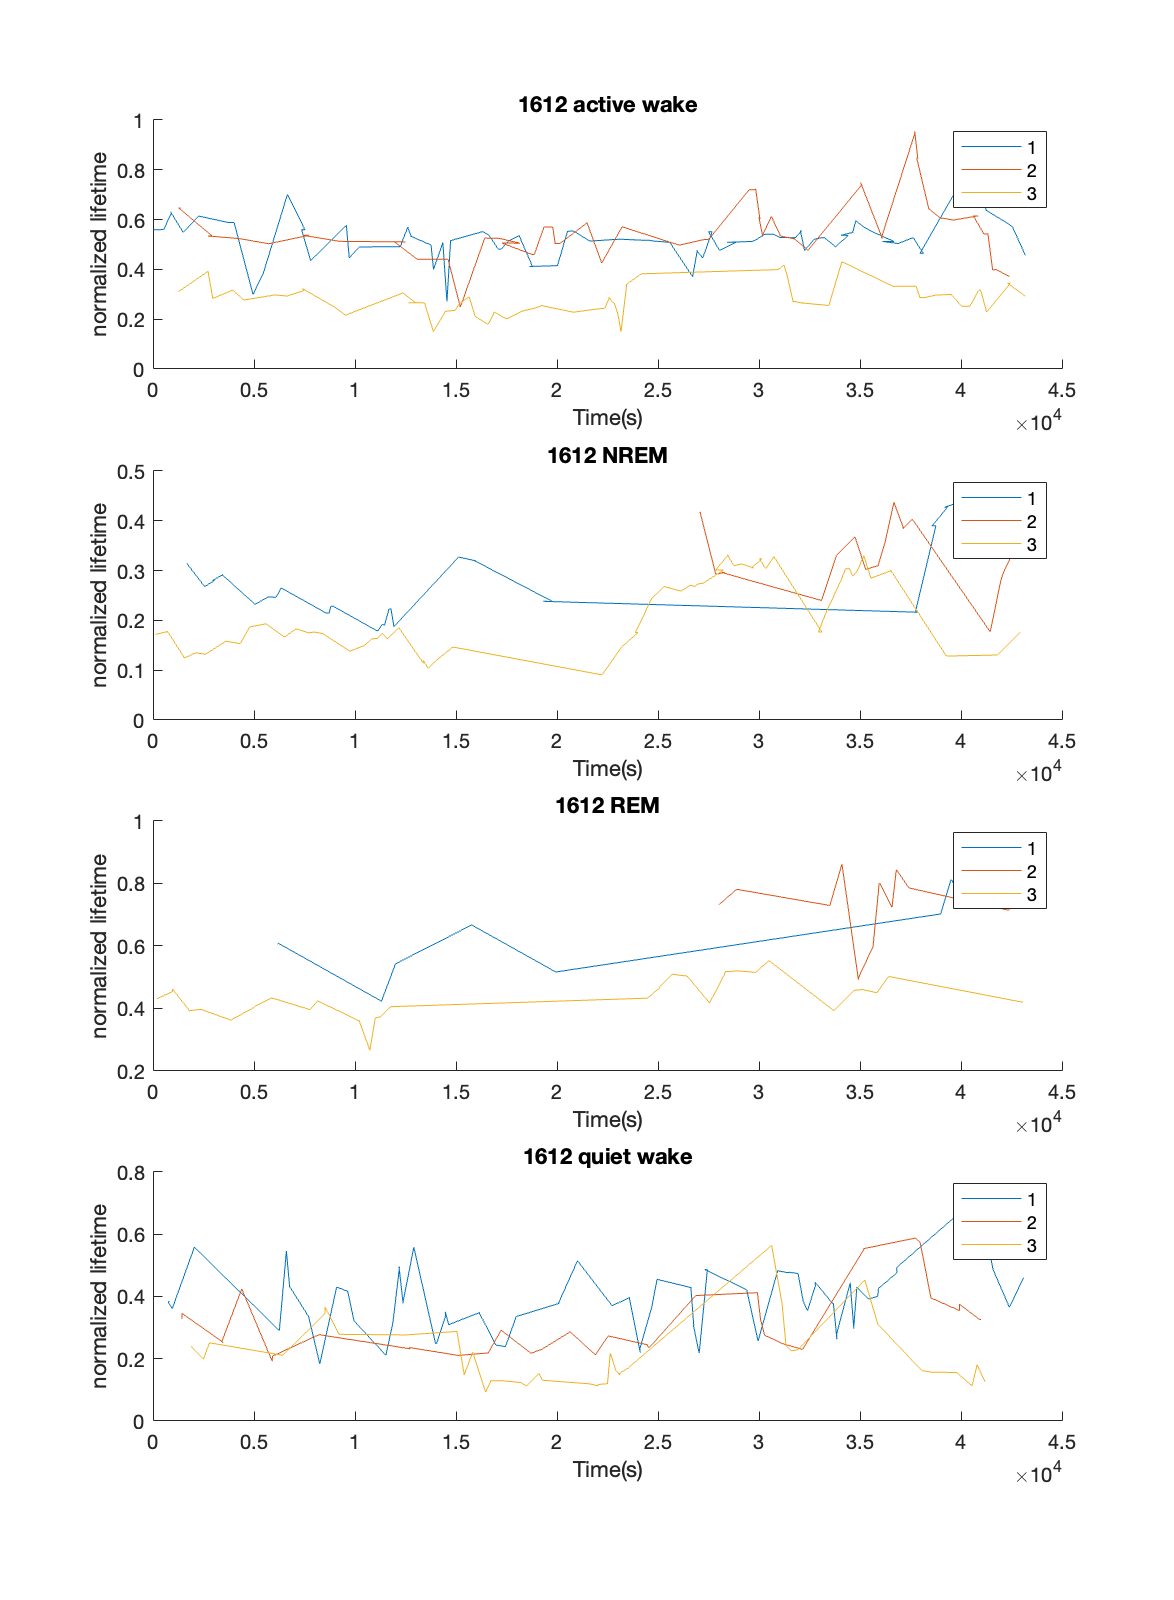

figure1=figure;
figure1.Position=[10 10 1100 1500];

CR_plot1=subplot(4,1,1,'Parent',figure1);
hold(CR_plot1,'on')
plot(t1(median_time_1a),lft1(median_time_1a))
plot(t2(median_time_1b),lft2(median_time_1b))
plot(t3(median_time_1c),lft3(median_time_1c))
legend('1','2','3')
title('1612 active wake')
ylabel('normalized lifetime')
xlabel('Time(s)')
hold(CR_plot1,'off')


CR_plot2=subplot(4,1,2,'Parent',figure1);
hold(CR_plot2,'on')
plot(t1(median_time_2a),lft1(median_time_2a))
plot(t2(median_time_2b),lft2(median_time_2b))
plot(t3(median_time_2c),lft3(median_time_2c))
legend('1','2','3')
title('1612 NREM')
ylabel('normalized lifetime')
xlabel('Time(s)')
hold(CR_plot2,'off')

CR_plot3=subplot(4,1,3,'Parent',figure1);
hold(CR_plot3,'on')
plot(t1(median_time_3a),lft1(median_time_3a))
plot(t2(median_time_3b),lft2(median_time_3b))
plot(t3(median_time_3c),lft3(median_time_3c))
legend('1','2','3')
title('1612 REM')
ylabel('normalized lifetime')
xlabel('Time(s)')
hold(CR_plot3,'off')


CR_plot4=subplot(4,1,4,'Parent',figure1);
hold(CR_plot4,'on')
plot(t1(median_time_4a),lft1(median_time_4a))
plot(t2(median_time_4b),lft2(median_time_4b))
plot(t3(median_time_4c),lft3(median_time_4c))
legend('1','2','3')
title('1612 quiet wake')
ylabel('normalized lifetime')
xlabel('Time(s)')
hold(CR_plot4,'off')

saveas(figure1,'/Volumes/PcSSDA/1612_CR_lft.png')

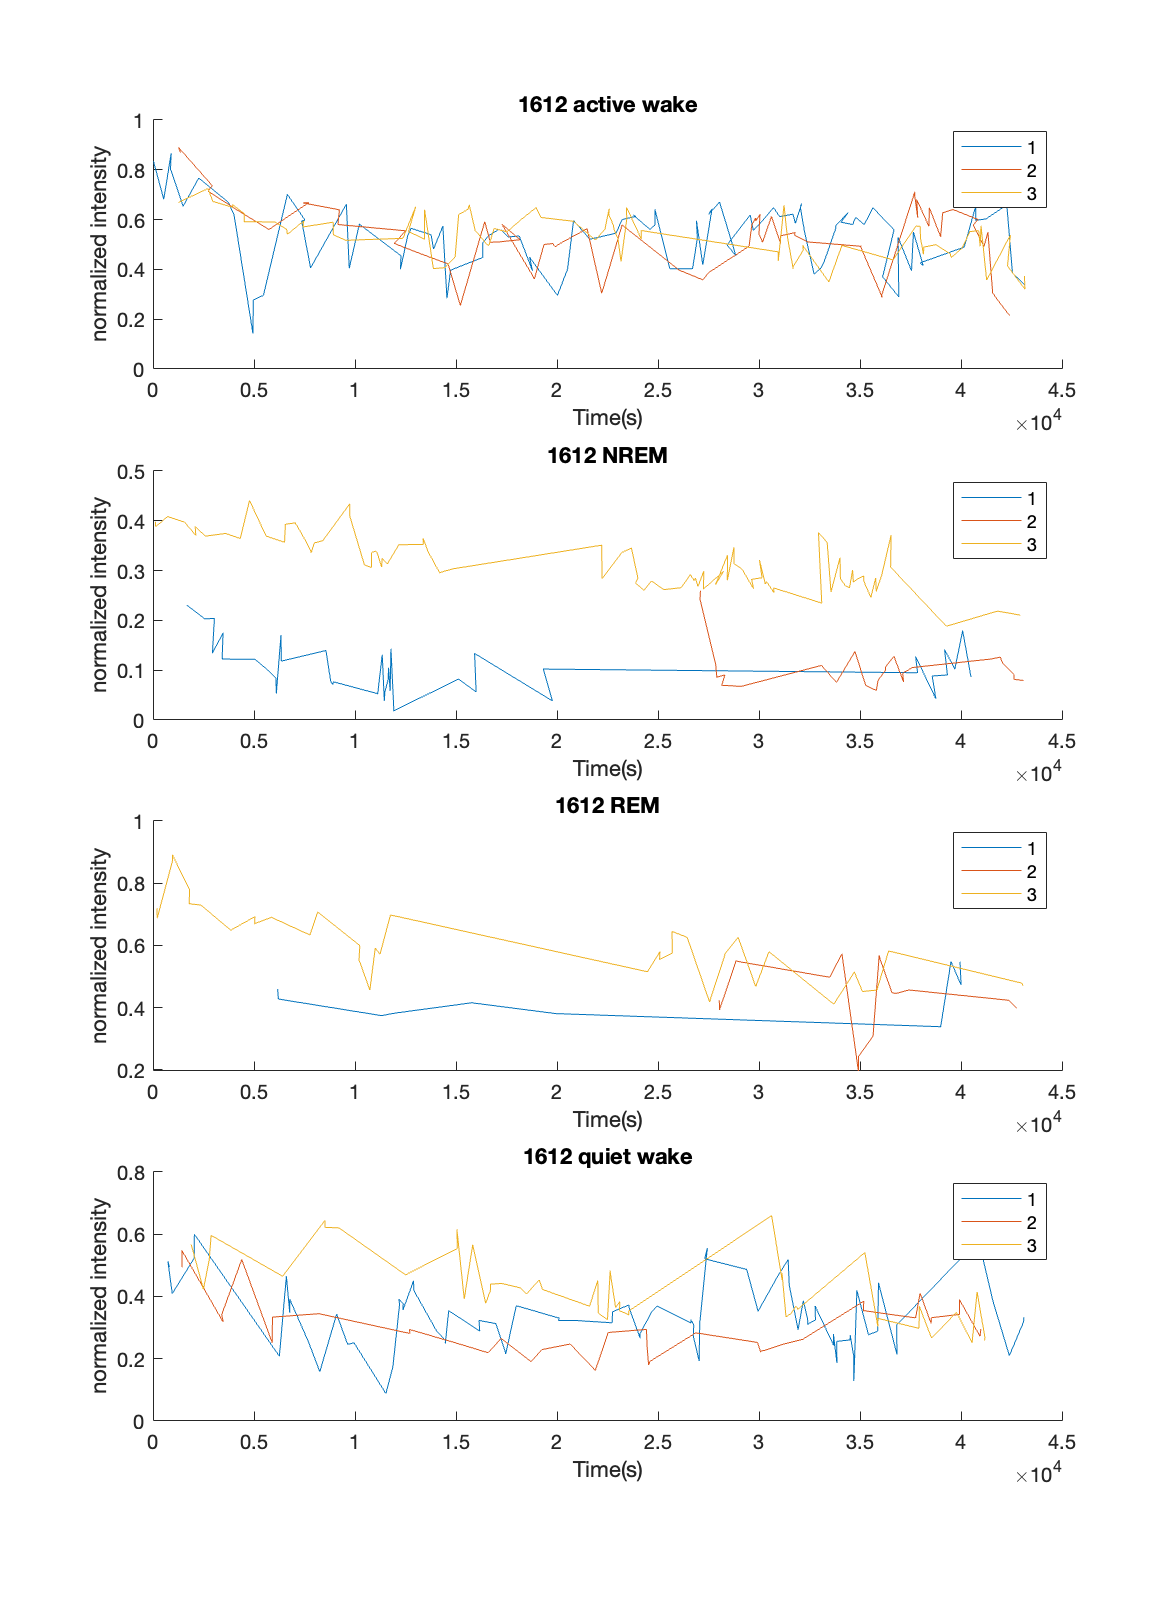

figure1=figure;
figure1.Position=[10 10 1100 1500];

CR_plot1=subplot(4,1,1,'Parent',figure1);
hold(CR_plot1,'on')
plot(t1(median_time_1a),intensity1(median_time_1a))
plot(t2(median_time_1b),intensity2(median_time_1b))
plot(t3(median_time_1c),intensity3(median_time_1c))
legend('1','2','3')
title('1612 active wake')
ylabel('normalized intensity')
xlabel('Time(s)')
hold(CR_plot1,'off')


CR_plot2=subplot(4,1,2,'Parent',figure1);
hold(CR_plot2,'on')
plot(t1(median_time_2a),intensity1(median_time_2a))
plot(t2(median_time_2b),intensity2(median_time_2b))
plot(t3(median_time_2c),intensity3(median_time_2c))
legend('1','2','3')
title('1612 NREM')
ylabel('normalized intensity')
xlabel('Time(s)')
hold(CR_plot2,'off')

CR_plot3=subplot(4,1,3,'Parent',figure1);
hold(CR_plot3,'on')
plot(t1(median_time_3a),intensity1(median_time_3a))
plot(t2(median_time_3b),intensity2(median_time_3b))
plot(t3(median_time_3c),intensity3(median_time_3c))
legend('1','2','3')
title('1612 REM')
ylabel('normalized intensity')
xlabel('Time(s)')
hold(CR_plot3,'off')


CR_plot4=subplot(4,1,4,'Parent',figure1);
hold(CR_plot4,'on')
plot(t1(median_time_4a),intensity1(median_time_4a))
plot(t2(median_time_4b),intensity2(median_time_4b))
plot(t3(median_time_4c),intensity3(median_time_4c))
legend('1','2','3')
title('1612 quiet wake')
ylabel('normalized intensity')
xlabel('Time(s)')
hold(CR_plot4,'off')

saveas(figure1,'/Volumes/PcSSDA/1612_CR_intensity.png')

cd('/Volumes/PcSSDA/1611/20220302_1611_SW_003')
load('median_information.mat')
t1=time_z_all_darkonly;
lft1=(tau_empTrunc_all_darkonly-min(tau_empTrunc_all_darkonly))/range(tau_empTrunc_all_darkonly);
intensity1=(intensity_all_darkonly-min(intensity_all_darkonly))/range(intensity_all_darkonly);
median_time_1a=median_time_1;
median_time_2a=median_time_2;
median_time_3a=median_time_3;
median_time_4a=median_time_4;
cd('/Volumes/PcSSDA/1611/20220316_1611_SW_004')
load('median_information.mat')
t2=time_z_all_darkonly;
lft2=(tau_empTrunc_all_darkonly-min(tau_empTrunc_all_darkonly))/range(tau_empTrunc_all_darkonly);
intensity2=(intensity_all_darkonly-min(intensity_all_darkonly))/range(intensity_all_darkonly);
median_time_1b=median_time_1;
median_time_2b=median_time_2;
median_time_3b=median_time_3;
median_time_4b=median_time_4;
cd('/Volumes/PcSSDA/1611/20220325_1611_SW_005')
load('median_information.mat')
t3=time_z_all_darkonly;
lft3=(tau_empTrunc_all_darkonly-min(tau_empTrunc_all_darkonly))/range(tau_empTrunc_all_darkonly);
intensity3=(intensity_all_darkonly-min(intensity_all_darkonly))/range(intensity_all_darkonly);
median_time_1c=median_time_1;
median_time_2c=median_time_2;
median_time_3c=median_time_3;
median_time_4c=median_time_4;

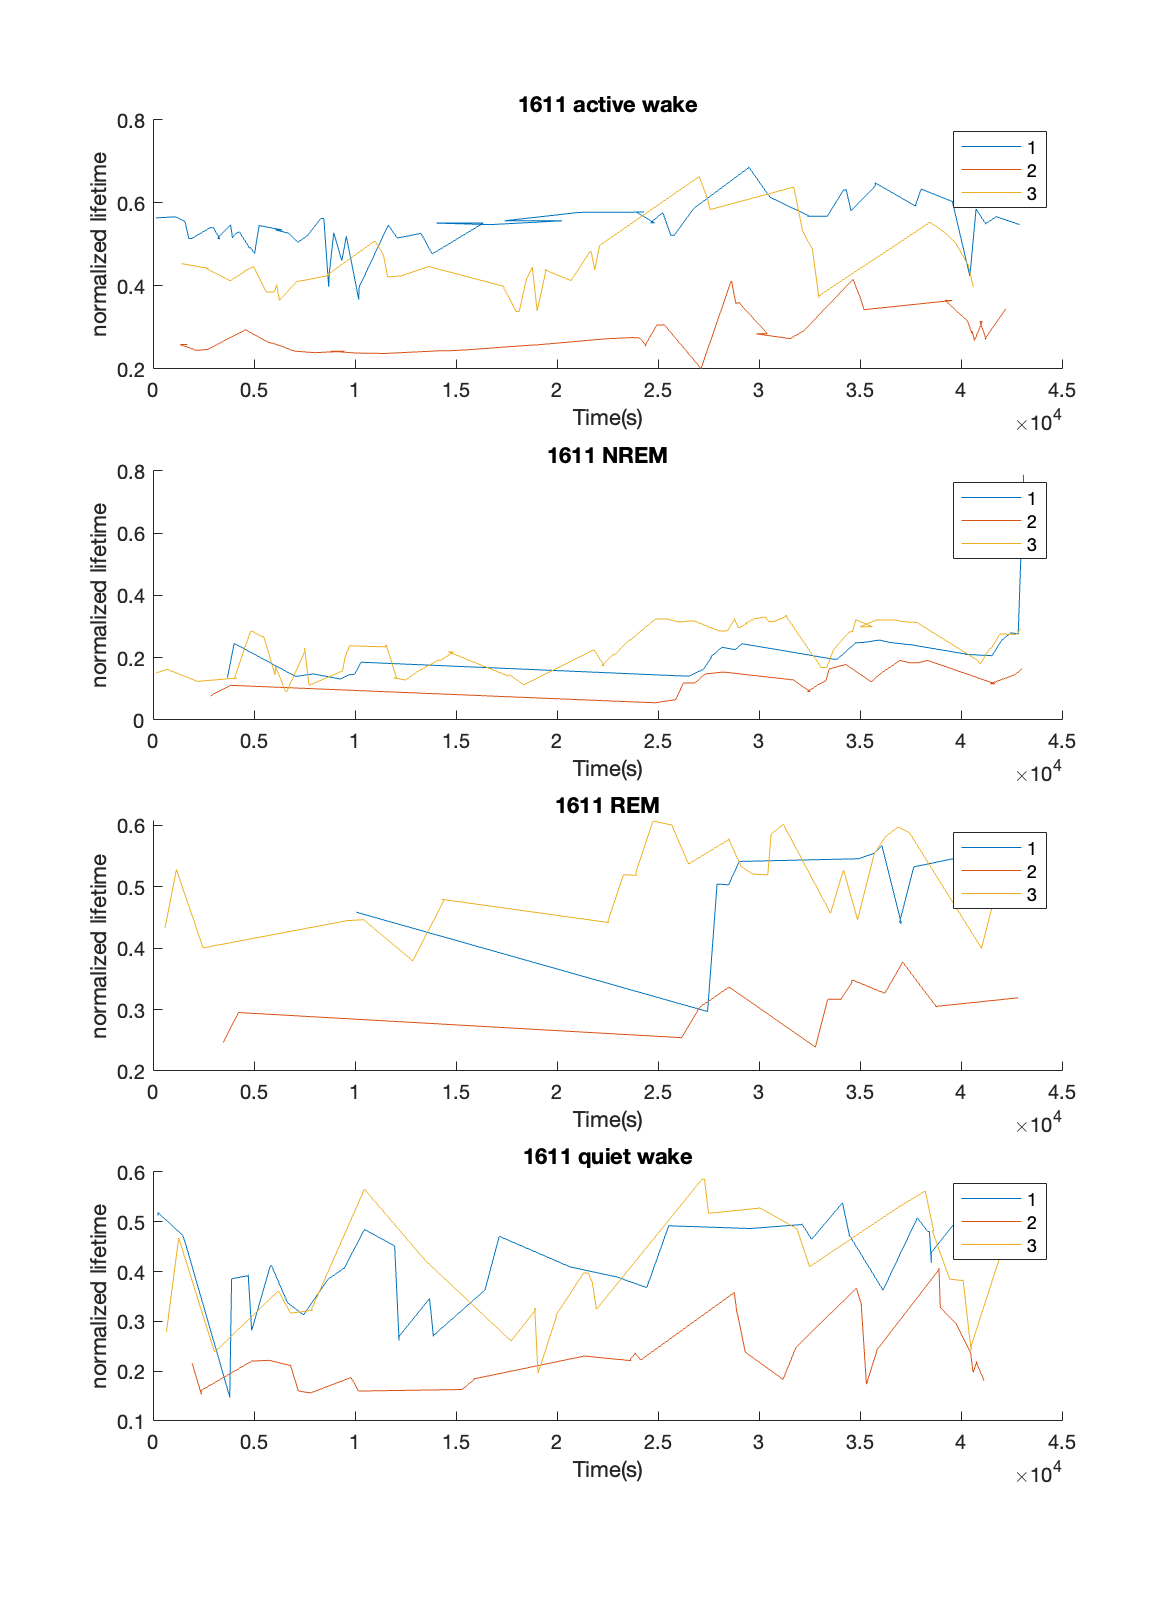

figure1=figure;
figure1.Position=[10 10 1100 1500];

CR_plot1=subplot(4,1,1,'Parent',figure1);
hold(CR_plot1,'on')
plot(t1(median_time_1a),lft1(median_time_1a))
plot(t2(median_time_1b),lft2(median_time_1b))
plot(t3(median_time_1c),lft3(median_time_1c))
legend('1','2','3')
title('1611 active wake')
ylabel('normalized lifetime')
xlabel('Time(s)')
hold(CR_plot1,'off')


CR_plot2=subplot(4,1,2,'Parent',figure1);
hold(CR_plot2,'on')
plot(t1(median_time_2a),lft1(median_time_2a))
plot(t2(median_time_2b),lft2(median_time_2b))
plot(t3(median_time_2c),lft3(median_time_2c))
legend('1','2','3')
title('1611 NREM')
ylabel('normalized lifetime')
xlabel('Time(s)')
hold(CR_plot2,'off')

CR_plot3=subplot(4,1,3,'Parent',figure1);
hold(CR_plot3,'on')
plot(t1(median_time_3a),lft1(median_time_3a))
plot(t2(median_time_3b),lft2(median_time_3b))
plot(t3(median_time_3c),lft3(median_time_3c))
legend('1','2','3')
title('1611 REM')
ylabel('normalized lifetime')
xlabel('Time(s)')
hold(CR_plot3,'off')


CR_plot4=subplot(4,1,4,'Parent',figure1);
hold(CR_plot4,'on')
plot(t1(median_time_4a),lft1(median_time_4a))
plot(t2(median_time_4b),lft2(median_time_4b))
plot(t3(median_time_4c),lft3(median_time_4c))
legend('1','2','3')
title('1611 quiet wake')
ylabel('normalized lifetime')
xlabel('Time(s)')
hold(CR_plot4,'off')

saveas(figure1,'/Volumes/PcSSDA/1611_CR_lft.png')

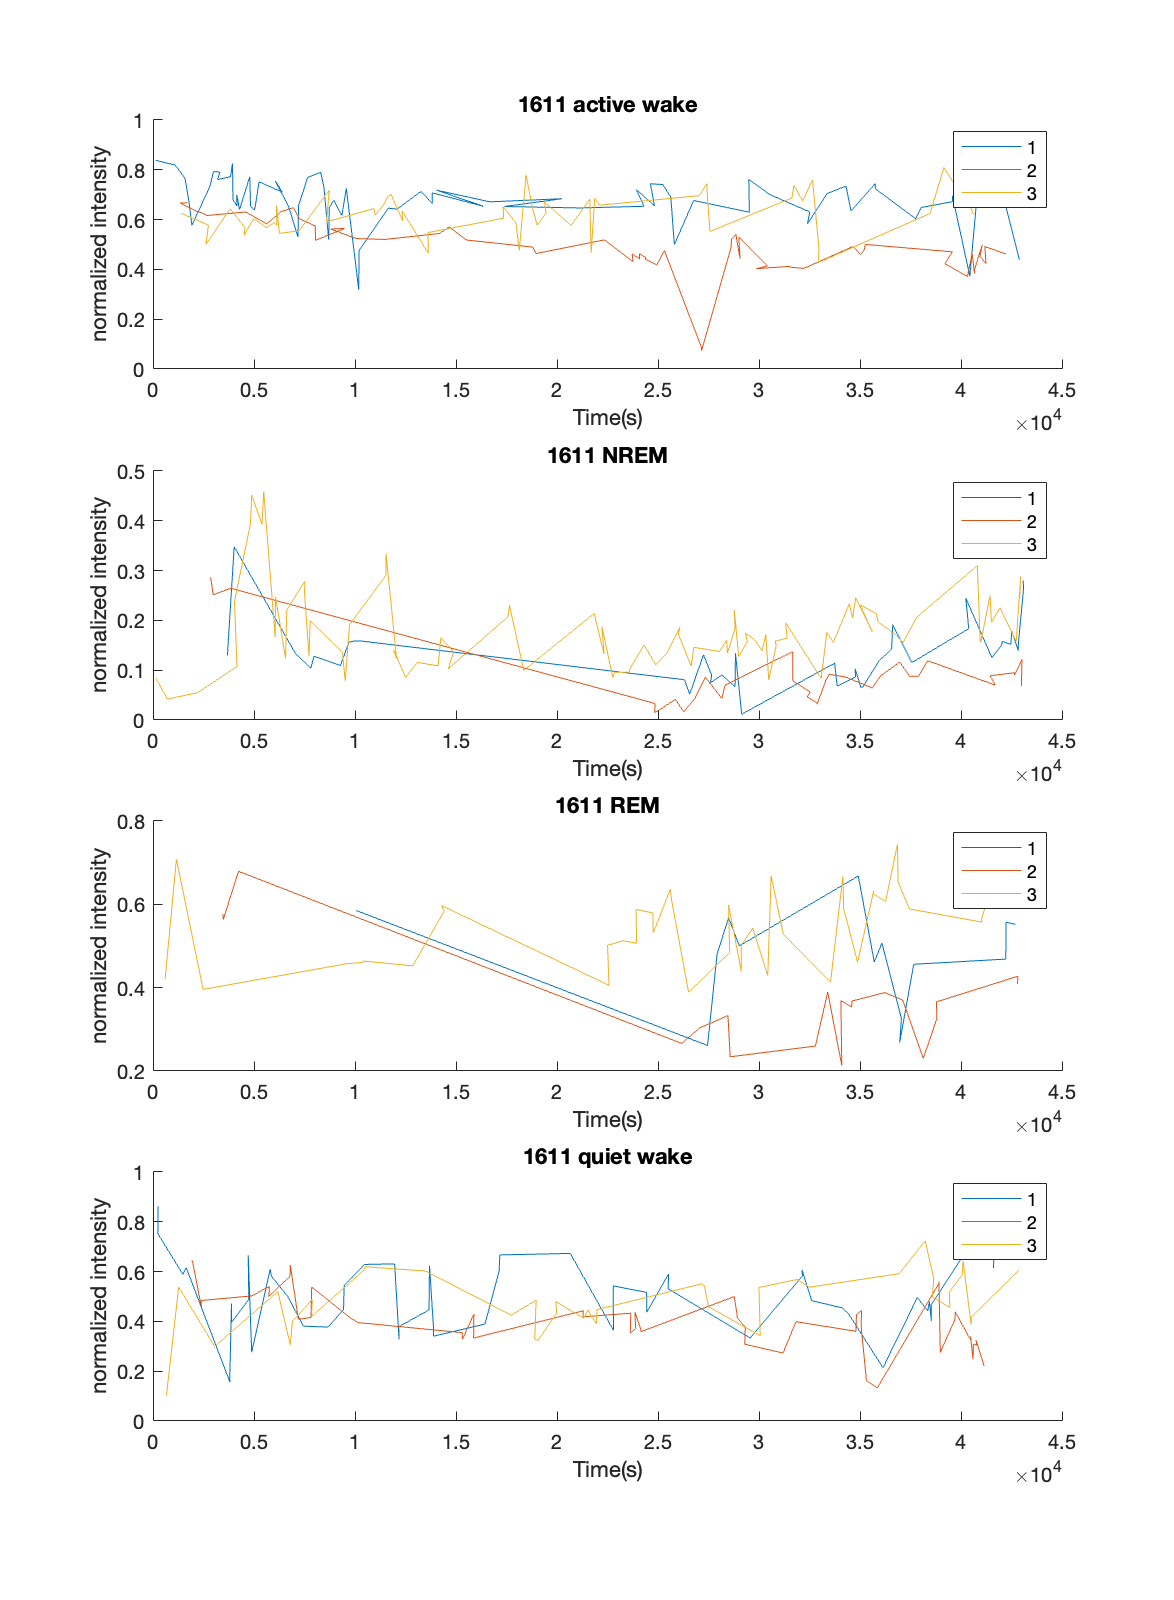

figure1=figure;
figure1.Position=[10 10 1100 1500];

CR_plot1=subplot(4,1,1,'Parent',figure1);
hold(CR_plot1,'on')
plot(t1(median_time_1a),intensity1(median_time_1a))
plot(t2(median_time_1b),intensity2(median_time_1b))
plot(t3(median_time_1c),intensity3(median_time_1c))
legend('1','2','3')
title('1611 active wake')
ylabel('normalized intensity')
xlabel('Time(s)')
hold(CR_plot1,'off')


CR_plot2=subplot(4,1,2,'Parent',figure1);
hold(CR_plot2,'on')
plot(t1(median_time_2a),intensity1(median_time_2a))
plot(t2(median_time_2b),intensity2(median_time_2b))
plot(t3(median_time_2c),intensity3(median_time_2c))
legend('1','2','3')
title('1611 NREM')
ylabel('normalized intensity')
xlabel('Time(s)')
hold(CR_plot2,'off')

CR_plot3=subplot(4,1,3,'Parent',figure1);
hold(CR_plot3,'on')
plot(t1(median_time_3a),intensity1(median_time_3a))
plot(t2(median_time_3b),intensity2(median_time_3b))
plot(t3(median_time_3c),intensity3(median_time_3c))
legend('1','2','3')
title('1611 REM')
ylabel('normalized intensity')
xlabel('Time(s)')
hold(CR_plot3,'off')


CR_plot4=subplot(4,1,4,'Parent',figure1);
hold(CR_plot4,'on')
plot(t1(median_time_4a),intensity1(median_time_4a))
plot(t2(median_time_4b),intensity2(median_time_4b))
plot(t3(median_time_4c),intensity3(median_time_4c))
legend('1','2','3')
title('1611 quiet wake')
ylabel('normalized intensity')
xlabel('Time(s)')
hold(CR_plot4,'off')

saveas(figure1,'/Volumes/PcSSDA/1611_CR_intensity.png')

cd('/Volumes/PcSSDA/1610/20220219_1610_SW_002')
load('median_information.mat')
t1=time_z_all_darkonly;
lft1=(tau_empTrunc_all_darkonly-min(tau_empTrunc_all_darkonly))/range(tau_empTrunc_all_darkonly);
intensity1=(intensity_all_darkonly-min(intensity_all_darkonly))/range(intensity_all_darkonly);
median_time_1a=median_time_1;
median_time_2a=median_time_2;
median_time_3a=median_time_3;
median_time_4a=median_time_4;
cd('/Volumes/PcSSDA/1610/20220314_1610_SW_003')
load('median_information.mat')
t2=time_z_all_darkonly;
lft2=(tau_empTrunc_all_darkonly-min(tau_empTrunc_all_darkonly))/range(tau_empTrunc_all_darkonly);
intensity2=(intensity_all_darkonly-min(intensity_all_darkonly))/range(intensity_all_darkonly);
median_time_1b=median_time_1;
median_time_2b=median_time_2;
median_time_3b=median_time_3;
median_time_4b=median_time_4;
cd('/Volumes/PcSSDA/1610/20220328_1610_SW_005')
load('median_information.mat')
t3=time_z_all_darkonly;
lft3=(tau_empTrunc_all_darkonly-min(tau_empTrunc_all_darkonly))/range(tau_empTrunc_all_darkonly);
intensity3=(intensity_all_darkonly-min(intensity_all_darkonly))/range(intensity_all_darkonly);
median_time_1c=median_time_1;
median_time_2c=median_time_2;
median_time_3c=median_time_3;
median_time_4c=median_time_4;

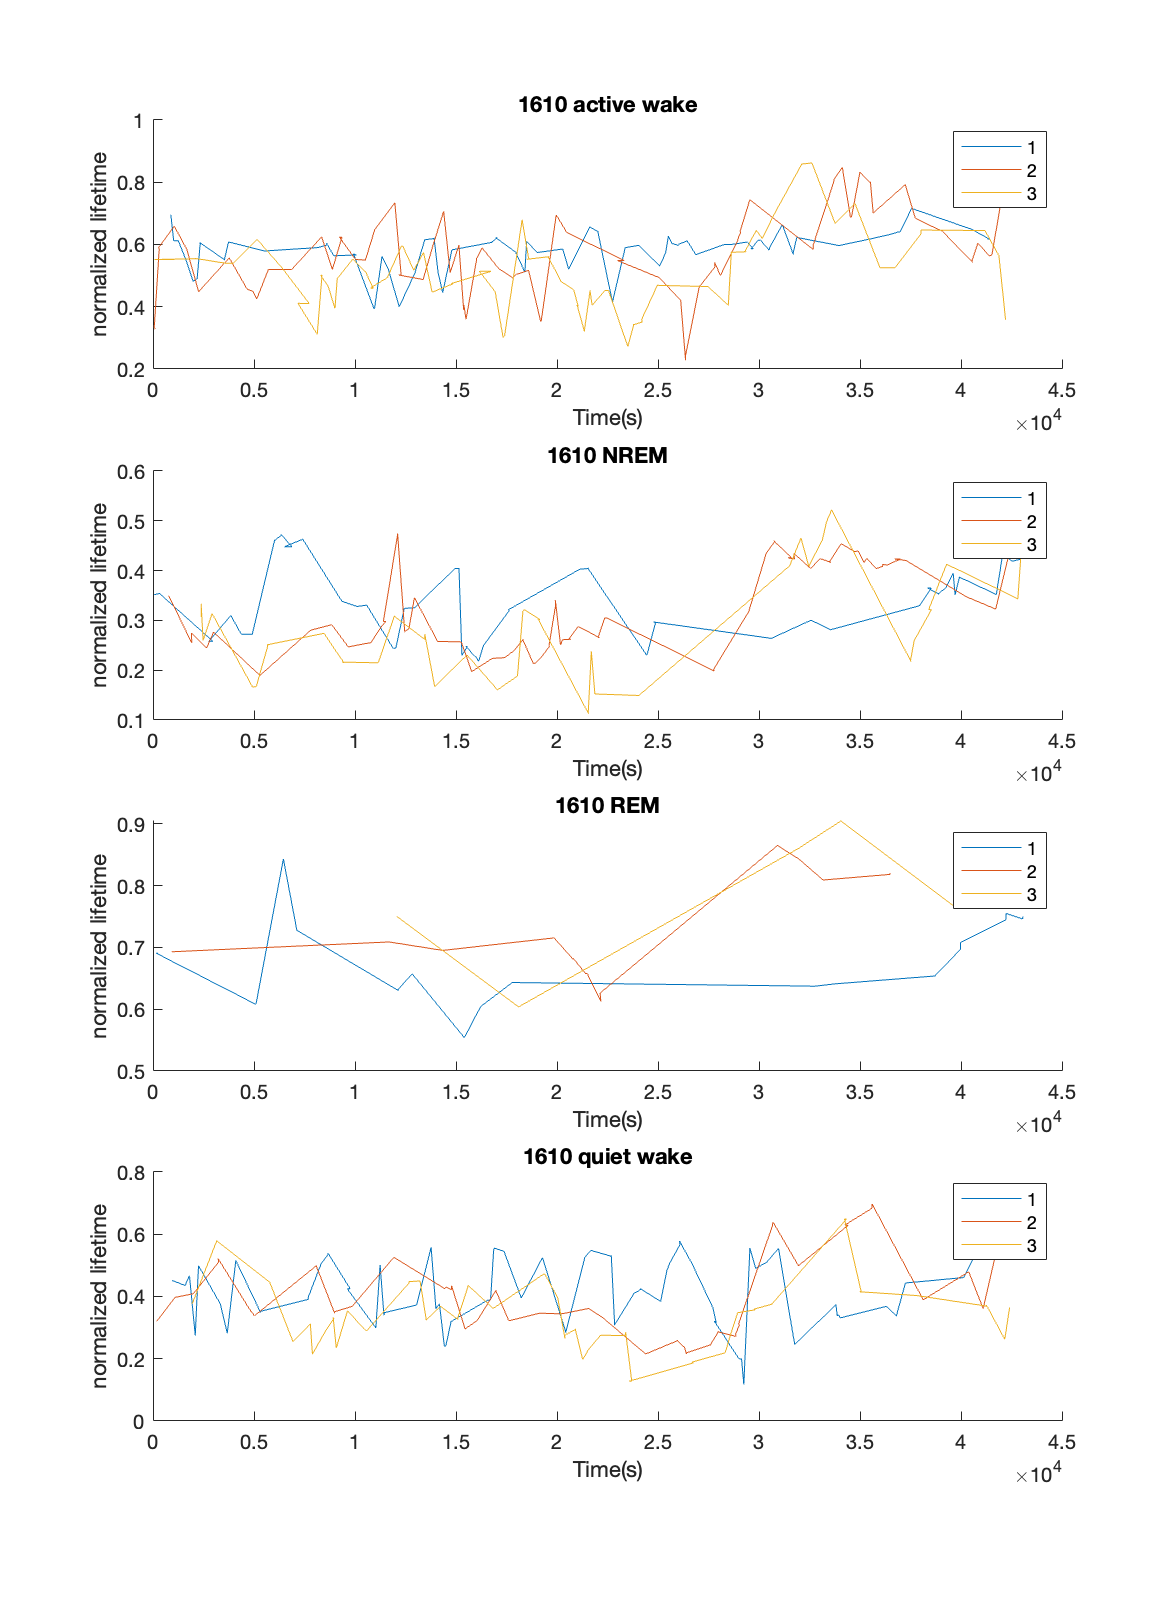

figure1=figure;
figure1.Position=[10 10 1100 1500];

CR_plot1=subplot(4,1,1,'Parent',figure1);
hold(CR_plot1,'on')
plot(t1(median_time_1a),lft1(median_time_1a))
plot(t2(median_time_1b),lft2(median_time_1b))
plot(t3(median_time_1c),lft3(median_time_1c))
legend('1','2','3')
title('1610 active wake')
ylabel('normalized lifetime')
xlabel('Time(s)')
hold(CR_plot1,'off')


CR_plot2=subplot(4,1,2,'Parent',figure1);
hold(CR_plot2,'on')
plot(t1(median_time_2a),lft1(median_time_2a))
plot(t2(median_time_2b),lft2(median_time_2b))
plot(t3(median_time_2c),lft3(median_time_2c))
legend('1','2','3')
title('1610 NREM')
ylabel('normalized lifetime')
xlabel('Time(s)')
hold(CR_plot2,'off')

CR_plot3=subplot(4,1,3,'Parent',figure1);
hold(CR_plot3,'on')
plot(t1(median_time_3a),lft1(median_time_3a))
plot(t2(median_time_3b),lft2(median_time_3b))
plot(t3(median_time_3c),lft3(median_time_3c))
legend('1','2','3')
title('1610 REM')
ylabel('normalized lifetime')
xlabel('Time(s)')
hold(CR_plot3,'off')


CR_plot4=subplot(4,1,4,'Parent',figure1);
hold(CR_plot4,'on')
plot(t1(median_time_4a),lft1(median_time_4a))
plot(t2(median_time_4b),lft2(median_time_4b))
plot(t3(median_time_4c),lft3(median_time_4c))
legend('1','2','3')
title('1610 quiet wake')
ylabel('normalized lifetime')
xlabel('Time(s)')
hold(CR_plot4,'off')

saveas(figure1,'/Volumes/PcSSDA/1610_CR_lft.png')

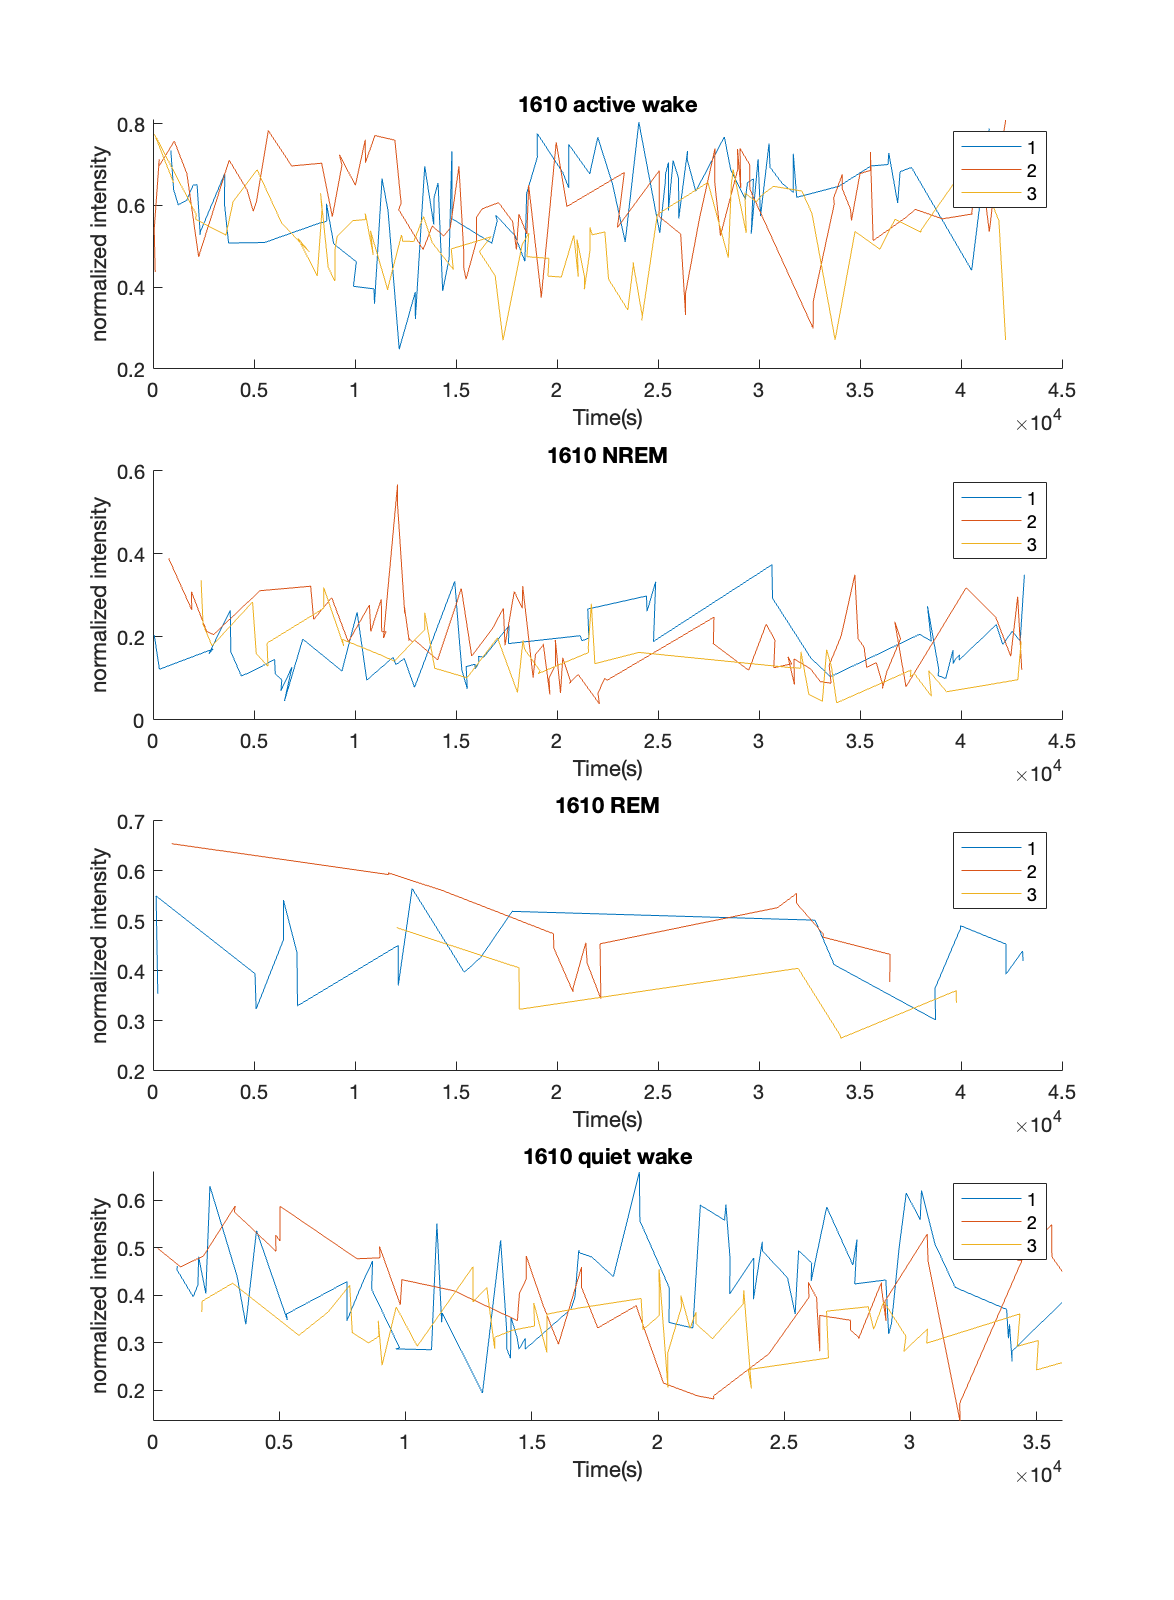

figure1=figure;
figure1.Position=[10 10 1100 1500];

CR_plot1=subplot(4,1,1,'Parent',figure1);
hold(CR_plot1,'on')
plot(t1(median_time_1a),intensity1(median_time_1a))
plot(t2(median_time_1b),intensity2(median_time_1b))
plot(t3(median_time_1c),intensity3(median_time_1c))
legend('1','2','3')
title('1610 active wake')
ylabel('normalized intensity')
xlabel('Time(s)')
hold(CR_plot1,'off')


CR_plot2=subplot(4,1,2,'Parent',figure1);
hold(CR_plot2,'on')
plot(t1(median_time_2a),intensity1(median_time_2a))
plot(t2(median_time_2b),intensity2(median_time_2b))
plot(t3(median_time_2c),intensity3(median_time_2c))
legend('1','2','3')
title('1610 NREM')
ylabel('normalized intensity')
xlabel('Time(s)')
hold(CR_plot2,'off')

CR_plot3=subplot(4,1,3,'Parent',figure1);
hold(CR_plot3,'on')
plot(t1(median_time_3a),intensity1(median_time_3a))
plot(t2(median_time_3b),intensity2(median_time_3b))
plot(t3(median_time_3c),intensity3(median_time_3c))
legend('1','2','3')
title('1610 REM')
ylabel('normalized intensity')
xlabel('Time(s)')
hold(CR_plot3,'off')


CR_plot4=subplot(4,1,4,'Parent',figure1);
hold(CR_plot4,'on')
plot(t1(median_time_4a),intensity1(median_time_4a))
plot(t2(median_time_4b),intensity2(median_time_4b))
plot(t3(median_time_4c),intensity3(median_time_4c))
legend('1','2','3')
title('1610 quiet wake')
ylabel('normalized intensity')
xlabel('Time(s)')
xlim([0 36000])
hold(CR_plot4,'off')

saveas(figure1,'/Volumes/PcSSDA/1610_CR_intensity.png')